# Programa base

## Inicialização

clear all; close all; clc;
addpath([pwd, '\functions']);
addpath([pwd, '\Resultados']);

## Dados

%Mandril - caso conico, rfm>rim
rim = 15; %raio inicial mandril - caso cilindro, assume rc=rim
rfm = 15; %raio final mandril
zim = -500; %z inicio mandril
zfm = 1000; %z final mandril
%Zona util do mandril
zig = 0; %z inicio da zona de enrolamento geodésico
zi = 0; %z inicio do enrolamento tem de ser igual a zig
zfg = 300; %z final da zona de enrolamento geodésico
%Alfa inicial zona geodésica (em zi)
alfainicio = 20; %alfa em graus. domínio: ]-90,90]
%Coeficiente de escorregamento
niu = 0.14;
lambda1 = niu;
%Incremento na curva
ds = 2;
dsta = 2; %ds no turnaround
%Propriedades do material
%largura de banda
b = 10;
%number of rovings
NR = 10;
%roving width (mm)
RW = b / NR;
%TEX value (g/km)
TEX = 800;
%fibre volume content/ fibre mass content (%) - o que não se usa=0
fvc = 0;
fmc = 60;
%fibre density (g/cm3)
fibdens = 1.77;
%resin density (g/cm3)
resdens = 1.2;
%Número de paths
NP = 6;
%Velocidade da máquina
vel = 1.5; %multiplica pelo tempo necessário para cada passo
%Outputs
nomeoutput = '04.03.2016_rc75_b10_-500,0,300,1000,alfa20'; %nome da pasta e ficheiros (sem espaços)
filepath = 'C:\Users\Rodrigo\Dropbox\Tese\Programa';
%Trajectórias
gravartrajectorias = 's'; %Se for para gravar, escrever 's' se nao, escrever outra coisa
%CNC
cnc = 's';
gravarcnc = 's'; %Se for para gravar, escrever 's' se nao, escrever outra coisa
%Distância da cabeça a ao mandril - distância fixa
D = 50;
%Sections - sobreposições só funcionam com secções rectangulares
seccoes = 'rectangular'; %rectangular ou eliptical
belip = 1; %espessura medida da fibra no caso eliptico
%Sobreposições
sobre = 'sobreposiçao2'; %'sobreposição1' - 1 ciclo. 'sobreposição2' - todos os ciclos 'sobreposição3' - matriz reorganizada ainda não funcional

## Datos estudio 1:

% var_ini.b = 5;
% var_ini.rim = 30;
% var_ini.rfm = 50;
% var_ini.zim = 0;
% var_ini.zi = 100;
% var_ini.zfg = 300;
% var_ini.zfm = 600;
% var_ini.alfainicio = 75;
% var_ini.lambda1 = 0.14;

## Datos estudio 2:

% var_ini.b = 5;
% var_ini.rim = 30;
% var_ini.rfm = 50;
% var_ini.zim = 0;
% var_ini.zi = 100;
% var_ini.zfg = 300;
% var_ini.zfm = 600;
% var_ini.alfainicio = 75;
% var_ini.lambda1 = 0.14;
b = 5;
rim = 30;
rfm = 50;
zim = 0;
zi = 100;
zfg = 300;
zfm = 600;
alfainicio = 75;
lambda1 = 0.14;

## Datos estudio 3:

## Datos estudio 4:

Grabar en excel:

datos_entrada = {
    'rim', rim;
    'rfm', rfm;
    'zim', zim;
    'zfm', zfm;
    'zig', zig;
    'zi', zi;
    'zfg', zfg;
    'alfainicio', alfainicio;
    'niu', niu;
    'lambda1', lambda1;
    'ds', ds;
    'dsta', dsta;
    'b', b;
    'NR', NR;
    'RW', RW;
    'TEX', TEX;
    'fvc', fvc;
    'fmc', fmc;
    'fibdens', fibdens;
    'resdens', resdens;
    'NP', NP;
    'vel', vel;
    'nomeoutput', nomeoutput;
    'filepath', filepath;
    'gravartrajectorias', gravartrajectorias;
    'cnc', cnc;
    'gravarcnc', gravarcnc;
    'D', D;
    'seccoes', seccoes;
    'belip', belip;
    'sobre', sobre;
    };
RIM = struct('rim', rim);
%writecell(datos_entrada, 'trayectorias2.xlsx', 'Sheet', 'Datos de entrada', 'Range', 'A1');

## Machine Parameters

%Reference
RefA = 0;
RefX = 0;
RefY = 260; %distancia do eixo Y ao fim da cabeça
RefB = 0;
RefZ = 0;
RefC = 0;
%Dimensions
Xmin = 165.15; %mm
Xmax = 2644.7; %mm
Ymin = -120; %mm
Ymax = 311; %mm
Zmin = 0; %mm
Zmax = 364; %mm
Cmin = -50; %º
Cmax = 50; %º
POew = 50; %mm
POe = 0; %mm
YawR = 260; %mm
%Velocity
VA = 150; %360º/min
VX = 1; %m/s
VY = 0.5; %m/s
VB = 115; %360º/min
VZ = 0.5; %m/s
VC = 100; %360º/min
%%%%%%%%%%%%% Página 3 %%%%%%%%%%%%
%Acceleration
AA = 8; %360º/min
AX = 4; %m/s
AY = 30; %m/s
AB = 60; %360º/min
AZ = 1; %m/s
AC = 45; %360º/min
%Resolution
RA = 360; %inc/360º
RX = 1; %inc/mm
RY = -1; %inc/mm
RB = 360; %inc/360º
RZ = 1; %inc/mm
RC = 360; %inc/360º
%Processing time
minproc = 0.03; %minimium processing time (s)
%Velocidades Máximas - inc/s
VAmax = abs(VA * RA / 60);
VXmax = abs(VX * 1000 * RX);
VYmax = abs(VY * 1000 * RY);
VBmax = abs(VB * RB / 60);
VZmax = abs(VZ * 1000 * RZ);
VCmax = abs(VC * RC / 60);
%Acelerações máximas
AAmax = abs(AA * RA);
AXmax = abs(AX * 60 * 1000 * RX);
AYmax = abs(AY * 60 * 1000 * RY);
ABmax = abs(AB * RB);
AZmax = abs(AZ * 60 * 1000 * RZ);
ACmax = abs(AC * RC);

Grabar en excel los parámetros de entrada:

datos_maquina = {
    'RefA', RefA;
    'RefX', RefX;
    'RefY', RefY;
    'RefB', RefB;
    'RefZ', RefZ;
    'RefC', RefC;
    'Xmin', Xmin;
    'Xmax', Xmax;
    'Ymin', Ymin;
    'Ymax', Ymax;
    'Zmin', Zmin;
    'Zmax', Zmax;
    'Cmin', Cmin;
    'Cmax', Cmax;
    'POew', POew;
    'POe', POe;
    'YawR', YawR;
    'VA', VA;
    'VX', VX;
    'VY', VY;
    'VB', VB;
    'VZ', VZ;
    'VC', VC;
    'AA', AA;
    'AX', AX;
    'AY', AY;
    'AB', AB;
    'AZ', AZ;
    'AC', AC;
    'RA', RA;
    'RX', RX;
    'RY', RY;
    'RB', RB;
    'RZ', RZ;
    'RC', RC;
    'minproc', minproc;
    'VAmax', VAmax;
    'VXmax', VXmax;
    'VYmax', VYmax;
    'VBmax', VBmax;
    'VZmax', VZmax;
    'VCmax', VCmax;
    'AAmax', AAmax;
    'AXmax', AXmax;
    'AYmax', AYmax;
    'ABmax', ABmax;
    'AZmax', AZmax;
    'ACmax', ACmax;
    };
%writecell(datos_maquina, 'trayectorias2.xlsx', 'Sheet', 'Parametros de la maquina', 'Range', 'A1');

## Cálculos iniciais

alfai = alfainicio * pi / 180; %alfa em rad
lm = zfm - zim; %comprimento do mandril
lg = zfg - zig; %comprimento zona geodésica
dm = rfm - rim; %diferença de raio do mandril
rig = ((zig * dm / lm) + rim - (dm * zim / lm)); %raio no inicio da zona geodésica
ri = ((zi * dm / lm) + rim - (dm * zim / lm)); %raio na secção do inicio do enrolamento
rfg = ((zfg * dm / lm) + rim - (dm * zim / lm)); %raio no final da zona geodésica
tau = atan(dm / lm);
zeroteta = (zfg + zig) / 2; %em coordenadas esféricas, o zero fica a meio
rc = rim; %se for cilindro fica com o raio menor do mandril
%Padrão cilindro
if rig == rfg
    %%%%%%%%%%%%% Página 4 %%%%%%%%%%%%
    beff = b / cos(alfai);
    nreal = 2 * pi * rc / beff;
    n1 = ceil(nreal);
end

% Espessura
fd = fmc * fibdens + (1 - fmc) * resdens;
esp = (fmc * (TEX / 100000) / ((RW / 10) * (fd - (1 - fmc) * resdens))) * 10;

Grabar en excel los cálculos iniciales:

calculos_iniciales = {
    'alfai', alfai;
    'lm', lm;
    'lg', lg;
    'dm', dm;
    'rig', rig;
    'ri', ri;
    'rfg', rfg;
    'tau', tau;
    'zeroteta', zeroteta;
    'rc', rc;
    'beff', beff;
    'nreal', nreal;
    'n1', n1;
    'fd', fd;
    'esp', esp;
    };

%writecell(calculos_iniciales, 'trayectorias2.xlsx', 'Sheet', 'Calculos iniciales', 'Range', 'A1');

## Mandril

Gerar Mandril

if rim == rfm
    tipomandril = 'cilindro'; %cilindro ou cone;
else
    tipomandril = 'cone';
end

switch lower(tipomandril)
    case {'cilindro'}
        tc = 0:pi / 20:2 * pi;
        k = 1;
        X = zeros(2, size(tc, 2));
        Y = zeros(2, size(tc, 2));
        Z = zeros(2, size(tc, 2));

        for tc = 0:pi / 20:2 * pi
            X(1, k) = rc * cos(tc);
            X(2, k) = rc * cos(tc);
            Y(1, k) = rc * sin(tc);
            Y(2, k) = rc * sin(tc);
            Z(1, k) = zim;
            Z(2, k) = zfm;
            k = k + 1;
        end

    case {'cone'}
        %Mandril
        %%%%%%%%%%%%% Página 5 %%%%%%%%%%%%
        tc = 0:pi / 20:2 * pi;
        k = 1;
        X = zeros(2, size(tc, 2));
        Y = zeros(2, size(tc, 2));
        Z = zeros(2, size(tc, 2));

        for tc = 0:pi / 20:2 * pi
            X(1, k) = rim * cos(tc);
            X(2, k) = rfm * cos(tc);
            Y(1, k) = rim * sin(tc);
            Y(2, k) = rfm * sin(tc);
            Z(1, k) = zim;
            Z(2, k) = zfm;
            k = k + 1;
        end

    otherwise
        %Mandril
        tc = 0:pi / 20:2 * pi;
        k = 1;
        X = zeros(2, size(tc, 2));
        Y = zeros(2, size(tc, 2));
        Z = zeros(2, size(tc, 2));

        for tc = 0:pi / 20:2 * pi
            X(1, k) = rim * cos(tc);
            X(2, k) = rim * cos(tc);
            Y(1, k) = rim * sin(tc);
            Y(2, k) = rim * sin(tc);
            Z(1, k) = zig;
            Z(2, k) = zig;
            k = k + 1;
        end

end

%Superfície parametrizada para coordenadas esféicas ou polares
if rim == rfm
    coordenadas = 'esfericas';
else
    coordenadas = 'polares';
end

switch lower(coordenadas)
    case {'polares'}
        % Superfície parametrizada do mandril em coordenadas polares
        %syms u v a(u) b(u) t
        %S=[a*cos(v),a*sin(v),b]; %S(u,v)=general shell of revolution
        % S=[cos(v)*cos(u), cos(v)*sin(u), sin(v)]
        %Cone
        syms fi ro
        %ro=((z*dm/lm)+rim-(dm*zim/lm));
        %%%%%%%%%%%%% Página 6 %%%%%%%%%%%%
        z = ro * lm / dm - rim * lm / dm + zim;
        S = [ro * cos(fi), ro * sin(fi), ro * lm / dm - rim * lm / dm + zim];
        % Propriedades da superfície - coordenadas polares
        %[chr,gg1,gg2,e,g,ev,eu,gv,gu]=Christoffel_funcao_1(S,u,v,ro)
        [chr, gg1, gg2, e, g, ero, efi, gro, gfi] = Christoffel_funcao_1(S, fi, ro, z);
        zlinha = diff(z, ro);
        z2linha = diff(zlinha, ro);
    case {'esfericas'}
        % Superfície parametrizada do mandril em coordenadas esfericas
        %Cilindro
        syms teta fi ro
        ro = rc / sin(teta);
        Se = [ro * sin(teta) * cos(fi), ro * sin(teta) * sin(fi), ro * cos(teta)];
        % Propriedades da superfície - coordenadas esfericas
        %[chr,gg1,gg2,e,g,ev,eu,gv,gu]=Christoffel_funcao_1(S,u,v,ro)
        [chr, gg1, gg2, e, g, eteta, efi, gteta, gfi] = Christoffel_funcao_1(Se, fi, teta, ro);
end

Index exceeds the number of array elements. Index must not exceed 1.

Error in indexing (line 962)
                R_tilde = builtin('subsref',L_tilde,Idx);

Error in cross (line 34)
    c2 = a(3).*b(1)-a(1).*b(3);

Error in 

Generar excel con superficie del mandril mandril:

mandril = {
    'tipomandril', tipomandril;
    'tc', tc;
    'X', X;
    'Y', Y;
    'Z', Z;
    'coordenadas', coordenadas;
    'ro', char(ro);
    'Se', char(Se);
    'Se', char(Se);
    'chr', char(chr);
    'gg1', char(gg1);
    'gg2', char(gg2);
    'e', char(e);
    'g', char(g);
    'eteta', char(eteta);
    'efi', char(efi);
    'gteta', char(gteta);
    'gfi', char(gfi);
    };

%writecell(mandril, 'trayectorias2.xlsx', 'Sheet', 'Superficie del mandril', 'Range', 'A1');

## Trajectória da zona útil 1

if rim == rfm
    traj1 = 'cilindros analitica';
else
    traj1 = 'cones analitica';
end

Unrecognized function or variable 'rim'.


switch lower(traj1)
    case {'cones analitica'}
 % Trajectoria geodésica para cones - Koussios
        %%%%%%%%%%%%% Página 7 %%%%%%%%%%%%
        c1 = sin(alfai) * ri; %começando a trajetoria em ri
        z = [];
        fi = [];
        fi1 = [];
        ro = [];
        alfa1 = [];
        lf = [];
        alfa1(1, 1) = alfai;
        z(1, 1) = zi;
        ro(1, 1) = ((z(1, 1) * dm / lm) + rim - (dm * zim / lm));
        fi1(1, 1) = (1 / sin(tau)) * (asin(c1 / rfg) - asin(c1 / ro(1, 1)));
        lf(1, 1) = 0;
        i = 1;

        while z(1, i) < zfg
            i = i + 1;
            z(1, i) = z(1, i - 1) + ds * cos(alfa1(1, i - 1)) * cos(tau);
            ro(1, i) = ((z(1, i) * dm / lm) + rim - (dm * zim / lm));
            fi1(1, i) = (1 / sin(tau)) * (asin(c1 / rfg) - asin(c1 / ro(1, i)));
            %alfa1(1,i)=atan((ro(1,i)*(fi1(1,i)-fi1(1,i-1)))/((z(1,i)-z(1,i-1))/cos(tau)));
            alfa1(1, i) = asin(c1 / ro(1, i));
            dalfadro(1, i) = (alfa1(1, i) - alfa1(1, i - 1)) / (ro(1, i) - ro(1, i - 1));
            lf(1, i) = lf(1, i - 1) + ds;
        end

        dalfadro(1, 1) = dalfadro(1, 2);

        if z(1, i) ~= zfg
            z(1, i) = zfg;
            ro(1, i) = ((z(1, i) * dm / lm) + rim - (dm * zim / lm));
            fi1(1, i) = (1 / sin(tau)) * (asin(c1 / rfg) - asin(c1 / ro(1, i)));
            %alfa1(1,i)=atan((ro(1,i)*(fi1(1,i)-fi1(1,i-1)))/((z(1,i)-z(1,i-1))/cos(tau)));
            alfa1(1, i) = asin(c1 / ro(1, i));
            lf(1, i) = lf(1, i - 1) + (z(1, i) - z(1, i - 1)) / (cos(tau) * cos(alfa1(1, i - 1)));
            dalfadro(1, i) = (alfa1(1, i) - alfa1(1, i - 1)) / (ro(1, i) - ro(1, i - 1));
        end

        %alfa=zeros(1,size(alfa1,2));
        alfa = alfa1;
        %passo extra
        %i=i+1;
        %zpe=z(1,i-1)+0.00001*cos(alfa1(1,i-1))*cos(tau);
        %rope=((zpe*dm/lm)+rim-(dm*zim/lm));
        %fi1pe=(1/sin(tau))*(asin(c1/rfg)-asin(c1/rope));
        %alfa1(1,i)=atan((rope*(fi1pe-fi1(1,i-1)))/((zpe-z(1,i-1))/cos(tau)));
        %%%%%%%%%%%%% Página 8 %%%%%%%%%%%%
        %for j=1:size(alfa,2)
        % alfa(1,j)=alfa1(1,j+1);
        %end
        fi(1, :) = fi1(1, :) - fi1(1, 1);
        %Cartesianas
        x = ro .* cos(fi);
        y = ro .* sin(fi);
    case {'cones integral'} %coordenadas polares
        % Cálculos iniciais
        fi = [];
        lf = [];
        alfa = []; t
        dalfadro = [];
        ro = [];
        z = [];
        alfa(1, 1) = alfai;
        fi(1, 1) = 0;
        lf(1, 1) = 0;
        z(1, 1) = zi;
        ro(1, 1) = ((z(1, 1) * dm / lm) + rim - (dm * zim / lm));
        n = 1;
        j = 1;
        %Cálculo de fi, alfa e Lf
        while z(1, n) < zfg
            ro(1, n + 1) = ro(1, n) + ds * cos(alfa(1, n)) * sin(tau);
            z(1, n + 1) = ro(1, n + 1) * lm / dm - rim * lm / dm + zim;
            dalfadro0 = -0.5 * ero * tan(alfa(1, n)) / gg1(1, 1);
            dalfadro1 = -0.5 * ero * tan(alfa(1, n)) / gg1(1, 1);
            dalfadro0 = double(subs(dalfadro0, 'ro', ro(1, n)));
            dalfadro0 = double(subs(dalfadro0, 'fi', fi(1, n)));
            dalfadro1 = double(subs(dalfadro1, 'ro', ro(1, n + 1)));
            dalfadro1 = double(subs(dalfadro1, 'fi', fi(1, n)));
            dalfadro(1, n) = dalfadro0;
            alfa(1, n + 1) = alfa(1, n) + (ro(1, n + 1) - ro(1, n)) * (dalfadro0 + dalfadro1) / 2;
            E1 = vpa(subs(gg1(1, 1), 'ro', ro(1, n)));
            E1 = vpa(subs(E1, 'fi', fi(1, n)));
            G1 = vpa(subs(gg1(2, 2), 'ro', ro(1, n)));
            G1 = vpa(subs(G1, 'fi', fi(1, n)));
            %%%%%%%%%%%%% Página 9 %%%%%%%%%%%%
            E2 = vpa(subs(gg1(1, 1), 'ro', ro(1, n + 1)));
            E2 = vpa(subs(E1, 'fi', fi(1, n)));
            G2 = vpa(subs(gg1(2, 2), 'ro', ro(1, n + 1)));
            G2 = vpa(subs(G1, 'fi', fi(1, n)));
            n = n + 1;
            fi(1, n) = fi(1, n - 1) + 0.5 * (ro(1, n) - ro(1, n - 1)) * (tan(alfa(1, n - 1)) * sqrt(G1 / E1) + tan(alfa(1, n)) * sqrt(G2 / E2)); %verificar contas
            lf(1, n) = lf(1, n - 1) + 0.5 * (ro(1, n) - ro(1, n - 1)) * (sqrt(G1) / cos(alfa(1, n - 1)) + sqrt(G2) / cos(alfa(1, n))); %verificar contas
        end

        if z(1, n) ~= zfg
            z(1, n) = zfg;
            ro(1, n) = ((z(1, n) * dm / lm) + rim - (dm * zim / lm));
            dalfadro0 = -0.5 * ero * tan(alfa(1, n)) / gg1(1, 1);
            dalfadro1 = -0.5 * ero * tan(alfa(1, n)) / gg1(1, 1);
            dalfadro0 = double(subs(dalfadro0, 'ro', ro(1, n - 1)));
            dalfadro1 = double(subs(dalfadro1, 'ro', ro(1, n)));
            dalfadro(1, n) = dalfadro0;
            alfa(1, n) = alfa(1, n - 1) + (ro(1, n) - ro(1, n - 1)) * (dalfadro0 + dalfadro1) / 2;
            E1 = vpa(subs(gg1(1, 1), 'ro', ro(1, n - 1)));
            E1 = vpa(subs(E1, 'fi', fi(1, n - 1)));
            G1 = vpa(subs(gg1(2, 2), 'ro', ro(1, n - 1)));
            G1 = vpa(subs(G1, 'fi', fi(1, n - 1)));
            E2 = vpa(subs(gg1(1, 1), 'ro', ro(1, n)));
            E2 = vpa(subs(E1, 'fi', fi(1, n - 1)));
            G2 = vpa(subs(gg1(2, 2), 'ro', ro(1, n)));
            G2 = vpa(subs(G1, 'fi', fi(1, n - 1)));
            fi(1, n) = fi(1, n - 1) + 0.5 * (ro(1, n) - ro(1, n - 1)) * (tan(alfa(1, n - 1)) * sqrt(G1 / E1) + tan(alfa(1, n)) * sqrt(G2 / E2)); %verificar contas
            lf(1, n) = lf(1, n - 1) + 0.5 * (ro(1, n) - ro(1, n - 1)) * (sqrt(G1) / cos(alfa(1, n - 1)) + sqrt(G2) / cos(alfa(1, n))); %verificar contas
        end
        %Cartesianas
        x = ro .* cos(fi);
        y = ro .* sin(fi);
    case {'cilindros analitica'}
        %Trajectória geodésica para cilindros - hélices
        %Helice e superficie
        dz = ds * cos(alfai);
        z = [];
        z(1, :) = zi:dz:zfg;
        %%%%%%%%%%%%% Página 10 %%%%%%%%%%%%
        if z(1, size(z, 2)) ~= zfg
            z(1, size(z, 2) + 1) = zfg;
        end

        c = rc / tan(alfai);
        fi = z / c;
        x = rc * cos(fi);
        y = rc * sin(fi);
        %para dar continuidade estes dados são necessários no TA
        alfa = ones(1, size(x, 2)) .* alfai;
        lf = sqrt((fi .* rc) .^ 2 + (z - zig) .^ 2); %fazer contas outra vez
        tetai = atan(rc / (lg / 2));
        tetaf = pi - tetai;
        dalfadteta = zeros(1, size(x, 2));
        teta = atan(rc ./ (zeroteta - z));
        tetap = [];
        tetap(1, 1) = teta(1, 1);

        for n = 1:size(teta, 2)

            if teta(1, n) < 0
                tetap(1, n) = teta(1, n) + pi;
            else
                tetap(1, n) = teta(1, n);
            end

        end

        if z(1, size(z, 2)) ~= zfg
            z(1, size(z, 2) + 1) = zfg;
        end

    case {'cilindros integral'} %coordenadas esfericas
        %Cálculos iniciais
        tetai = atan(rc / (lg / 2 - zi));
        tetaf = pi - atan(rc / (lg / 2));
        fi = [];
        lf = [];
        alfa = [];
        dalfadteta = [];
        alfa(1, 1) = alfai;
        teta = [];
        teta1 = tetai;
        %%%%%%%%%%%%% Página 11 %%%%%%%%%%%%
        teta(1, 1) = teta1;
        tetap = [];
        tetap(1, 1) = tetai;
        fi(1, 1) = 0;
        lf(1, 1) = 0;
        n = 1;
        j = 1;
        % Cálculo de fi, alfa e Lf
        while tetap(1, n) < tetaf
            %Gerar teta para ds constante
            j = n + 1;
            teta(1, j) = teta1;
            teta2 = atan(1 / (- (ds * cos(alfa(1, n))) / rc + 1 / tan(teta1)));
            teta1 = teta2;

            if teta(1, j) < 0
                tetap(1, j) = teta(1, j) + pi;
            else
                tetap(1, j) = teta(1, j);
            end

            dalfadteta0 = 0.5 * eteta * tan(alfa(1, n)) / gg1(1, 1);
            dalfadteta1 = 0.5 * eteta * tan(alfa(1, n)) / gg1(1, 1);
            dalfadteta0 = double(subs(dalfadteta0, 'teta', tetap(1, n)));
            dalfadteta1 = double(subs(dalfadteta1, 'teta', tetap(1, n + 1)));
            dalfadteta(1, n) = dalfadteta0;
            alfa(1, n + 1) = alfa(1, n) + (tetap(1, n + 1) - tetap(1, n)) * (dalfadteta0 + dalfadteta1) / 2;
            E1 = vpa(subs(gg1(1, 1), 'teta', tetap(1, n)));
            E1 = vpa(subs(E1, 'fi', fi(1, n)));
            G1 = vpa(subs(gg1(2, 2), 'teta', tetap(1, n)));
            G1 = vpa(subs(G1, 'fi', fi(1, n)));
            E2 = vpa(subs(gg1(1, 1), 'teta', tetap(1, n + 1)));
            E2 = vpa(subs(E1, 'fi', fi(1, n)));
            G2 = vpa(subs(gg1(2, 2), 'teta', tetap(1, n + 1)));
            G2 = vpa(subs(G1, 'fi', fi(1, n)));
            n = n + 1;
            fi(1, n) = fi(1, n - 1) + 0.5 * (tetap(1, n) - tetap(1, n - 1)) * (tan(alfa(1, n - 1)) * sqrt(G1 / E1) + tan(alfa(1, n)) * sqrt(G2 / E2));
            lf(1, n) = lf(1, n - 1) + 0.5 * (tetap(1, n) - tetap(1, n - 1)) * (sqrt(G1) / cos(alfa(1, n - 1)) + sqrt(G2) / cos(alfa(1, n)));
            %%%%%%%%%%%%% Página 12 %%%%%%%%%%%%
        end

        %ultimo passo
        if tetap(1, n - 1) ~= tetaf
            tetap(1, n) = tetaf;
            dalfadteta0 = 0.5 * eteta * tan(alfa(1, n)) / gg1(1, 1);
            dalfadteta1 = 0.5 * eteta * tan(alfa(1, n)) / gg1(1, 1);
            dalfadteta0 = double(subs(dalfadteta0, 'teta', tetap(1, n)));
            dalfadteta1 = double(subs(dalfadteta1, 'teta', tetap(1, n + 1)));
            dalfadteta(1, n) = dalfadteta0;
            alfa(1, n + 1) = alfa(1, n) + (tetap(1, n + 1) - tetap(1, n)) * (dalfadteta0 + dalfadteta1) / 2;
            E1 = vpa(subs(gg1(1, 1), 'teta', tetap(1, n)));
            E1 = vpa(subs(E1, 'fi', fi(1, n)));
            G1 = vpa(subs(gg1(2, 2), 'teta', tetap(1, n)));
            G1 = vpa(subs(G1, 'fi', fi(1, n)));
            E2 = vpa(subs(gg1(1, 1), 'teta', tetap(1, n + 1)));
            E2 = vpa(subs(E1, 'fi', fi(1, n)));
            G2 = vpa(subs(gg1(2, 2), 'teta', tetap(1, n + 1)));
            G2 = vpa(subs(G1, 'fi', fi(1, n)));
            n = n + 1;
            fi(1, n) = fi(1, n - 1) + 0.5 * (tetap(1, n) - tetap(1, n - 1)) * (tan(alfa(1, n - 1)) * sqrt(G1 / E1) + tan(alfa(1, n)) * sqrt(G2 / E2));
            lf(1, n) = lf(1, n - 1) + 0.5 * (tetap(1, n) - tetap(1, n - 1)) * (sqrt(G1) / cos(alfa(1, n - 1)) + sqrt(G2) / cos(alfa(1, n)));
        end
        %Cartesianas
        ro = rc ./ sin(tetap);
        x = ro .* sin(tetap) .* cos(fi);
        y = ro .* sin(tetap) .* sin(fi);
        z = -ro .* cos(tetap) + zeroteta;
end

Grabar en excel el camino de ida:

helice_ida = {
    'traj1 ', traj1 ;
    'dz', dz;
    'z', z;
    'c', c;
    'fi', fi;
    'x', x;
    'y', y;
    'alfa', alfa;
    'lf', lf;
    'tetai', tetai;
    'tetaf', tetaf;
    'dalfadteta', dalfadteta;
    'teta', teta;
    'tetap', tetap;
    };
%writecell(helice_ida, 'trayectorias2.xlsx', 'Sheet', 'Helice ida', 'Range', 'A1');
HELICE_IDA = struct('Z1', z, 'Y1', y, 'X1', x);
graficas_multiples(HELICE_IDA, 'Hélice a la ida', {'Mandril', 'Hélice a la ida'}, RIM);

## Turnaround 1

if rim == rfm
    turnaround = 'cilindro';
else
    turnaround = 'cone';
end

switch lower(turnaround)
    case {'cilindro'}
        % Cálculos iniciais
        alfaita = alfa(1, size(alfa, 2));
        teta1 = tetaf;
        tetata = [];
        tetata(1, 1) = teta1;
        tetatap = [];
        tetatap(1, 1) = teta1;
        alfata = [];
        alfata(1, 1) = alfaita;
        fita = [];
        fita(1, 1) = fi(1, size(fi, 2));
        lfta = [];
        lfta(1, 1) = lf(1, size(lf, 2));
        dalfadtetata = [];
        dalfadtetata(1, 1) = dalfadteta(1, size(dalfadteta, 2));
        n = 1;
        j = 1;
        % Primeira metade
        while alfata(1, n) < pi / 2
            %Gerar teta para ds constante
            j = j + 1;
            tetata(1, j) = teta1;
            teta2 = atan(1 / (- (dsta * cos(alfata(1, n))) / rc + 1 / tan(teta1)));
            teta1 = teta2;
            %%%%%%%%%%%%% Página 14 %%%%%%%%%%%%
            if tetata(1, j) < 0
                tetatap(1, j) = tetata(1, j) + pi;
            else
                tetatap(1, j) = tetata(1, j);
            end

            %Cálculo das formas fundamentais em tetatap(1,n)
            E1 = vpa(subs(gg1(1, 1), 'teta', tetatap(1, n)));
            E1 = vpa(subs(E1, 'fi', fita(1, n)));
            G1 = vpa(subs(gg1(2, 2), 'teta', tetatap(1, n)));
            G1 = vpa(subs(G1, 'fi', fita(1, n)));
            L1 = vpa(subs(gg2(1, 1), 'teta', tetatap(1, n)));
            L1 = vpa(subs(L1, 'fi', fita(1, n)));
            N1 = vpa(subs(gg2(2, 2), 'teta', tetatap(1, n)));
            N1 = vpa(subs(N1, 'fi', fita(1, n)));
            %Cálculo de dalfadteta em tetatap(1,n)
            dalfadtetata0 = 0.5 * eteta * tan(alfata(1, n)) / gg1(1, 1) + lambda1 * ((sqrt(G1) / cos(alfata(1, n))) * (((cos(alfata(1, n)) ^ 2) * N1 / G1) + ((sin(alfata(1, n)) ^ 2) * L1 / E1)));
            %Cálculo das formas fundamentais em tetatap(1,n+1)
            E2 = vpa(subs(gg1(1, 1), 'teta', tetatap(1, n + 1)));
            E2 = vpa(subs(E2, 'fi', fita(1, n)));
            G2 = vpa(subs(gg1(2, 2), 'teta', tetatap(1, n + 1)));
            G2 = vpa(subs(G2, 'fi', fita(1, n)));
            L2 = vpa(subs(gg2(1, 1), 'teta', tetatap(1, n + 1)));
            L2 = vpa(subs(L2, 'fi', fita(1, n)));
            N2 = vpa(subs(gg2(2, 2), 'teta', tetatap(1, n + 1)));
            N2 = vpa(subs(N2, 'fi', fita(1, n)));
            %Cálculo de dalfadteta em tetatap(1,n)
            dalfadtetata1 = 0.5 * eteta * tan(alfata(1, n)) / gg1(1, 1) + lambda1 * ((sqrt(G2) / cos(alfata(1, n))) * (((cos(alfata(1, n)) ^ 2) * N2 / G2) + ((sin(alfata(1, n)) ^ 2) * L2 / E2)));
            dalfadtetata(1, n) = dalfadtetata0;
            %Cálculo de alfa
            alfata(1, n + 1) = alfata(1, n) + (tetatap(1, n + 1) - tetatap(1, n)) * (dalfadtetata0 + dalfadtetata1) / 2;
            %Cálculo de fi e Lf
            fita(1, n + 1) = fita(1, n) + 0.5 * (tetatap(1, n + 1) - tetatap(1, n)) * (tan(alfata(1, n)) * sqrt(G1 / E1) + tan(alfata(1, n + 1)) * sqrt(G2 / E2));
            lfta(1, n + 1) = lfta(1, n) + 0.5 * (tetatap(1, n + 1) - tetatap(1, n)) * (sqrt(G1) / cos(alfata(1, n)) + sqrt(G2) / cos(alfata(1, n + 1)));
            n = n + 1;
        end

        dalfadtetata(1, n) = dalfadtetata(1, n - 1);
        alfata(1, n) = pi / 2;
        %%%%%%%%%%%%% Página 15 %%%%%%%%%%%%
        % Dwell
        nmeio = n;
        alfatameio = alfata(1, n);
        fitameio = fita(1, n);
        dfita = dsta / rc;
        deltafita = fita(1, n) - fita(1, 1);
        fitafin1 = fita(1, n) + deltafita;
        fitafin2 = 2 * fitafin1;
        p = 1;

        while fitafin2 > p * 2 * pi
            p = p + 1;
        end

        dif = p * 2 * pi - fitafin2;

        if dif / 2 - pi / n1 >= 0
            fidwell = dif / 2 - pi / n1;
        else
            fidwell = dif / 2 + pi / n1;
        end

        while fita(1, n) < fitameio + fidwell
            n = n + 1;
            fita(1, n) = fita(1, n - 1) + dfita;
            lfta(1, n) = lfta(1, n - 1) + rc * dfita;
            alfata(1, n) = pi / 2;
            dalfadtetata(1, n) = dalfadtetata(1, n - 1);
            tetata(1, n) = tetata(1, n - 1);
            tetatap(1, n) = tetatap(1, n - 1);
        end

        fita(1, n) = fita(1, nmeio) + fidwell;
        lfta(1, n) = lfta(1, n - 1) + rc * (fita(1, n) - fita(1, n - 1));
        nfimrest = n;
        teta1 = tetatap(1, n);
        j = n;
        % Segunda metade
        parte2turnaround = 'simetrico';

        switch lower(parte2turnaround)
            case {'integral'}

                while alfata(1, n) < (pi - alfaita)
                    %Gerar teta para ds constante
                    j = j + 1;
                    tetata(1, j) = teta1;
                    %%%%%%%%%%%%% Página 16 %%%%%%%%%%%%
                    teta2 = atan(1 / (- (dsta * cos(alfata(1, n))) / rc + 1 / tan(teta1)));
                    teta1 = teta2;

                    if tetata(1, j) < 0
                        tetatap(1, j) = tetata(1, j) + pi;
                    else
                        tetatap(1, j) = tetata(1, j);
                    end

                    E1 = vpa(subs(gg1(1, 1), 'teta', tetatap(1, n)));
                    E1 = vpa(subs(E1, 'fi', fita(1, n)));
                    G1 = vpa(subs(gg1(2, 2), 'teta', tetatap(1, n)));
                    G1 = vpa(subs(G1, 'fi', fita(1, n)));
                    L1 = vpa(subs(gg2(1, 1), 'teta', tetatap(1, n)));
                    L1 = vpa(subs(L1, 'fi', fita(1, n)));
                    N1 = vpa(subs(gg2(2, 2), 'teta', tetatap(1, n)));
                    N1 = vpa(subs(N1, 'fi', fita(1, n)));
                    dalfadtetata0 = 0.5 * eteta * tan(alfata(1, n)) / gg1(1, 1) + lambda1 * ((sqrt(G1) / cos(alfata(1, n))) * (((cos(alfata(1, n)) ^ 2) * N1 / G1) + ((sin(alfata(1, n)) ^ 2) * L1 / E1)));
                    E2 = vpa(subs(gg1(1, 1), 'teta', tetatap(1, n + 1)));
                    E2 = vpa(subs(E2, 'fi', fita(1, n)));
                    G2 = vpa(subs(gg1(2, 2), 'teta', tetatap(1, n + 1)));
                    G2 = vpa(subs(G2, 'fi', fita(1, n)));
                    L2 = vpa(subs(gg2(1, 1), 'teta', tetatap(1, n + 1)));
                    L2 = vpa(subs(L2, 'fi', fita(1, n)));
                    N2 = vpa(subs(gg2(2, 2), 'teta', tetatap(1, n + 1)));
                    N2 = vpa(subs(N2, 'fi', fita(1, n)));
                    dalfadtetata1 = 0.5 * eteta * tan(alfata(1, n)) / gg1(1, 1) + lambda1 * ((sqrt(G2) / cos(alfata(1, n))) * (((cos(alfata(1, n)) ^ 2) * N2 / G2) + ((sin(alfata(1, n)) ^ 2) * L2 / E2)));
                    dalfadtetata(1, n) = dalfadtetata0;
                    alfata(1, n + 1) = alfata(1, n) + (tetatap(1, n + 1) - tetatap(1, n)) * (dalfadtetata0 + dalfadtetata1) / 2;
                    fita(1, n + 1) = fita(1, n) + 0.5 * (tetatap(1, n + 1) - tetatap(1, n)) * (tan(alfata(1, n)) * sqrt(G1 / E1) + tan(alfata(1, n + 1)) * sqrt(G2 / E2));
                    lfta(1, n + 1) = lfta(1, n) + 0.5 * (tetatap(1, n + 1) - tetatap(1, n)) * (sqrt(G1) / cos(alfata(1, n)) + sqrt(G2) / cos(alfata(1, n + 1)));
                    n = n + 1;
                end

            case {'simetrico'}

                for i = 0:nmeio - 1
                    n = n + 1;
                    fita(1, nfimrest + i) = fita(1, nfimrest) + fita(1, nmeio) - fita(1, nmeio - i);
                    %%%%%%%%%%%%% Página 17 %%%%%%%%%%%%
                    lfta(1, nfimrest + i) = lfta(1, nfimrest) + lfta(1, nmeio) - lfta(1, nmeio - i);
                    alfata(1, nfimrest + i) = alfata(1, nmeio) + (alfata(1, nmeio) - alfata(1, nmeio - i));
                    tetatap(1, nfimrest + i) = tetatap(1, nmeio - i);
                    tetata(1, nfimrest + i) = tetatap(1, nmeio - i);
                    dalfadtetata(1, nfimrest + i) = -dalfadtetata(1, nmeio - i);
                end

                n = n - 1;
        end

        nfinal = n;
        alfafinal = alfata(1, n);
        fitafinal = fita(1, n);
        % Cartesianas
        rota = rc ./ sin(tetatap);
        xta = rota .* sin(tetatap) .* cos(fita);
        yta = rota .* sin(tetatap) .* sin(fita);
        zta = -rota .* cos(tetatap) + zeroteta;
    case {'cone'}
        % Cálculos iniciais
        alfaita = alfa(1, size(alfa, 2));
        %Padrão - sempre a assumir rfg>rig
        beff = b / cos(alfaita);
        nreal = 2 * pi * ro(1, size(ro, 2) - 1) / beff;
        n1 = ceil(nreal);
        alfata = [];
        alfata(1, 1) = alfaita;
        alfata21 = [];
        alfata21(1, 1) = pi - alfai;
        fita = [];
        fita(1, 1) = fi(1, size(fi, 2));
        fita21 = [];
        fita21(1, 1) = 0;
        lfta = [];
        lfta(1, 1) = lf(1, size(lf, 2));
        lfta21 = [];
        lfta21(1, 1) = 0;
        dalfadrota = [];
        dalfadrota(1, 1) = dalfadro(1, size(dalfadro, 2));
        %%%%%%%%%%%%% Página 18 %%%%%%%%%%%%
        dalfadrota21 = [];
        dalfadrota21(1, 1) = -dalfadro(1, 1);
        rota = [];
        rota(1, 1) = ro(1, size(ro, 2));
        rota21 = [];
        rota21(1, 1) = rig;
        zta = [];
        zta(1, 1) = z(1, size(z, 2));
        zta21 = [];
        zta21(1, 1) = zig;
        n = 1;
        nta = 1;

        if alfaita < 0
            % Primeira metade do TA1
            while alfata(1, n) >- pi / 2
                rota(1, n + 1) = rota(1, n) + ds * cos(alfata(1, n)) * sin(tau);
                zta(1, n + 1) = rota(1, n + 1) * lm / dm - rim * lm / dm + zim;
                %Cálculo das formas fundamentais em rota(1,n)
                E1 = vpa(subs(gg1(1, 1), 'ro', rota(1, n)));
                E1 = vpa(subs(E1, 'fi', fita(1, n)));
                G1 = vpa(subs(gg1(2, 2), 'ro', rota(1, n)));
                G1 = vpa(subs(G1, 'fi', fita(1, n)));
                L1 = vpa(subs(gg2(1, 1), 'ro', rota(1, n)));
                L1 = vpa(subs(L1, 'fi', fita(1, n)));
                N1 = vpa(subs(gg2(2, 2), 'ro', rota(1, n)));
                N1 = vpa(subs(N1, 'fi', fita(1, n)));
                %Cálculo de dalfadro em rota(1,n)
                dalfadrota0 = -0.5 * ero * tan(alfata(1, n)) / gg1(1, 1) + lambda1 * ((sqrt(G1) / cos(alfata(1, n))) * (((cos(alfata(1, n)) ^ 2) * N1 / G1) + ((sin(alfata(1, n)) ^ 2) * L1 / E1)));
                lambdacenas2(1, n) = lambda1 * ((sqrt(G1) / cos(alfata(1, n))) * (((cos(alfata(1, n)) ^ 2) * N1 / G1) + ((sin(alfata(1, n)) ^ 2) * L1 / E1)));
                lambdacenas21(1, n) = double(subs(lambdacenas2(1, n), 'ro', rota(1, n)));
                %Cálculo das formas fundamentais em rota(1,n+1)
                E2 = vpa(subs(gg1(1, 1), 'ro', rota(1, n + 1)));
                E2 = vpa(subs(E2, 'fi', fita(1, n)));
                G2 = vpa(subs(gg1(2, 2), 'ro', rota(1, n + 1)));
                G2 = vpa(subs(G2, 'fi', fita(1, n)));
                L2 = vpa(subs(gg2(1, 1), 'ro', rota(1, n + 1)));
                L2 = vpa(subs(L2, 'fi', fita(1, n)));
                N2 = vpa(subs(gg2(2, 2), 'ro', rota(1, n + 1)));
                %%%%%%%%%%%%% Página 19 %%%%%%%%%%%%
                N2 = vpa(subs(N2, 'fi', fita(1, n)));
                %Cálculo de dalfadro em rota(1,n)
                dalfadrota1 = -0.5 * ero * tan(alfata(1, n)) / gg1(1, 1) + lambda1 * ((sqrt(G2) / cos(alfata(1, n))) * (((cos(alfata(1, n)) ^ 2) * N2 / G2) + ((sin(alfata(1, n)) ^ 2) * L2 / E2)));
                dalfadrota0 = double(subs(dalfadrota0, 'ro', rota(1, n)));
                dalfadrota1 = double(subs(dalfadrota1, 'ro', rota(1, n + 1)));
                dalfadrota(1, n) = dalfadrota0;
                %Cálculo de alfa
                alfata(1, n + 1) = alfata(1, n) + (rota(1, n + 1) - rota(1, n)) * (dalfadrota0 + dalfadrota1) / 2;
                %Cálculo de fi e Lf
                fita(1, n + 1) = fita(1, n) + 0.5 * (rota(1, n + 1) - rota(1, n)) * (tan(alfata(1, n)) * sqrt(G1 / E1) + tan(alfata(1, n + 1)) * sqrt(G2 / E2));
                lfta(1, n + 1) = lfta(1, n) + 0.5 * (rota(1, n + 1) - rota(1, n)) * (sqrt(G1) / cos(alfata(1, n)) + sqrt(G2) / cos(alfata(1, n + 1)));
                n = n + 1;
            end

            dalfadrota(1, n) = dalfadrota(1, n - 1);
            dfi = fi(1, size(fi, 2)) - fi(1, 1);
            dfita = fita(1, size(fita, 2)) - fita(1, 1);
            fitameio = fita(1, n);
            nmeio = n;
            disp('fim TA1')
            % Primeira metade do TA2
            alfata21(1, 1) = -pi - alfai;

            while alfata21(1, nta) <- pi / 2
                rota21(1, nta + 1) = rota21(1, nta) - ds * cos(alfata21(1, nta)) * sin(tau);
                zta21(1, nta + 1) = rota21(1, nta + 1) * lm / dm - rim * lm / dm + zim;
                %Cálculo das formas fundamentais em tetatap(1,n)
                E1 = vpa(subs(gg1(1, 1), 'ro', rota21(1, nta)));
                E1 = vpa(subs(E1, 'fi', fita21(1, nta)));
                G1 = vpa(subs(gg1(2, 2), 'ro', rota21(1, nta)));
                G1 = vpa(subs(G1, 'fi', fita21(1, nta)));
                L1 = vpa(subs(gg2(1, 1), 'ro', rota21(1, nta)));
                L1 = vpa(subs(L1, 'fi', fita21(1, nta)));
                N1 = vpa(subs(gg2(2, 2), 'ro', rota21(1, nta)));
                N1 = vpa(subs(N1, 'fi', fita21(1, nta)));
                %%%%%%%%%%%%% Página 20 %%%%%%%%%%%%
                %Cálculo de dalfadteta em tetatap(1,n)
                dalfadrota0 = -0.5 * ero * tan(alfata21(1, nta)) / gg1(1, 1) - lambda1 * ((sqrt(G1) / cos(alfata21(1, nta))) * (((cos(alfata21(1, nta)) ^ 2) * N1 / G1) + ((sin(alfata21(1, nta)) ^ 2) * L1 / E1)));
                %dalfadrota0=-0.5*ero*tan(alfata21(1,nta))/gg1(1,1)+lambda1*((1/cos(alfata21(1,nta)))*(((zlinha+zlinha^3-rota21(1,nta)*z2linha)/(rota21(1,nta)*(1+zlinha^2)))*sin(alfata21(1,nta))^2+z2linha/(1+zlinha^2)));
                lambdacenas(1, nta) = lambda1 * ((sqrt(G1) / cos(alfata21(1, nta))) * (((cos(alfata21(1, nta)) ^ 2) * N1 / G1) + ((sin(alfata21(1, nta)) ^ 2) * L1 / E1)));
                lambdacenasz(1, nta) = lambda1 * ((1 / cos(alfata21(1, nta))) * (((zlinha + zlinha ^ 3 - rota21(1, nta) * z2linha) / (rota21(1, nta) * (1 + zlinha ^ 2))) * sin(alfata21(1, nta)) ^ 2 + z2linha / (1 + zlinha ^ 2)));
                geocenas(1, nta) = 0.5 * ero * tan(alfata21(1, nta)) / gg1(1, 1);
                %Cálculo das formas fundamentais em tetatap(1,n+1)
                E2 = vpa(subs(gg1(1, 1), 'ro', rota21(1, nta + 1)));
                E2 = vpa(subs(E2, 'fi', fita21(1, nta)));
                G2 = vpa(subs(gg1(2, 2), 'ro', rota21(1, nta + 1)));
                G2 = vpa(subs(G2, 'fi', fita21(1, nta)));
                L2 = vpa(subs(gg2(1, 1), 'ro', rota21(1, nta + 1)));
                L2 = vpa(subs(L2, 'fi', fita21(1, nta)));
                N2 = vpa(subs(gg2(2, 2), 'ro', rota21(1, nta + 1)));
                N2 = vpa(subs(N2, 'fi', fita21(1, nta)));
                %Cálculo de dalfadteta em tetatap(1,n)
                %dalfadrota1=-0.5*ero*tan(alfata21(1,nta))/gg1(1,1)+lambda1*((1/cos(alfata21(1,nta)))*(((zlinha+zlinha^3-rota21(1,nta+1)*z2linha)/(rota21(1,nta+1)*(1+zlinha^2)))*sin(alfata21(1,nta))^2+z2linha/(1+zlinha^2)));
                dalfadrota1 = -0.5 * ero * tan(alfata21(1, nta)) / gg1(1, 1) - lambda1 * ((sqrt(G2) / cos(alfata21(1, nta))) * (((cos(alfata21(1, nta)) ^ 2) * N2 / G2) + ((sin(alfata21(1, nta)) ^ 2) * L2 / E2)));
                dalfadrota0 = double(subs(dalfadrota0, 'ro', rota21(1, nta)));
                dalfadrota1 = double(subs(dalfadrota1, 'ro', rota21(1, nta + 1)));
                lambdacenas1(1, nta) = double(subs(lambdacenas(1, nta), 'ro', rota21(1, nta)));
                lambdacenasz1(1, nta) = double(subs(lambdacenasz(1, nta), 'ro', rota21(1, nta)));
                geocenas1(1, nta) = double(subs(geocenas(1, nta), 'ro', rota21(1, nta)));
                dalfadrota21(1, nta) = dalfadrota0;
                %Cálculo de alfa
                alfata21(1, nta + 1) = alfata21(1, nta) + abs(rota21(1, nta + 1) - rota21(1, nta)) * abs(dalfadrota0 + dalfadrota1) / 2;
                %Cálculo de fi e Lf
                fita21(1, nta + 1) = fita21(1, nta) + 0.5 * (rota21(1, nta + 1) - rota21(1, nta)) * (tan(alfata21(1, nta)) * sqrt(G1 / E1) + tan(alfata21(1, nta + 1)) * sqrt(G2 / E2));
                lfta21(1, nta + 1) = lfta21(1, nta) + 0.5 * (rota21(1, nta + 1) - rota21(1, nta)) * (sqrt(G1) / cos(alfata21(1, nta)) + sqrt(G2) / cos(alfata21(1, nta + 1)));
                nta = nta + 1;
            end

            %%%%%%%%%%%%% Página 21 %%%%%%%%%%%%
            nmeio2 = nta;
            disp('fim TA2')
            dalfadrota21(1, nta) = dalfadrota21(1, nta - 1);
            dfita21 = fita21(1, size(fita21, 2)) - fita21(1, 1);
        else
            % Primeira metade do TA1
            while alfata(1, n) < pi / 2
                rota(1, n + 1) = rota(1, n) + ds * cos(alfata(1, n)) * sin(tau);
                zta(1, n + 1) = rota(1, n + 1) * lm / dm - rim * lm / dm + zim;
                %Cálculo das formas fundamentais em rota(1,n)
                E1 = vpa(subs(gg1(1, 1), 'ro', rota(1, n)));
                E1 = vpa(subs(E1, 'fi', fita(1, n)));
                G1 = vpa(subs(gg1(2, 2), 'ro', rota(1, n)));
                G1 = vpa(subs(G1, 'fi', fita(1, n)));
                L1 = vpa(subs(gg2(1, 1), 'ro', rota(1, n)));
                L1 = vpa(subs(L1, 'fi', fita(1, n)));
                N1 = vpa(subs(gg2(2, 2), 'ro', rota(1, n)));
                N1 = vpa(subs(N1, 'fi', fita(1, n)));
                %Cálculo de dalfadro em rota(1,n)
                dalfadrota0 = -0.5 * ero * tan(alfata(1, n)) / gg1(1, 1) - lambda1 * ((sqrt(G1) / cos(alfata(1, n))) * (((cos(alfata(1, n)) ^ 2) * N1 / G1) + ((sin(alfata(1, n)) ^ 2) * L1 / E1)));
                lambdacenas2(1, n) = lambda1 * ((sqrt(G1) / cos(alfata(1, n))) * (((cos(alfata(1, n)) ^ 2) * N1 / G1) + ((sin(alfata(1, n)) ^ 2) * L1 / E1)));
                lambdacenas21(1, n) = double(subs(lambdacenas2(1, n), 'ro', rota(1, n)));
                %Cálculo das formas fundamentais em rota(1,n+1)
                E2 = vpa(subs(gg1(1, 1), 'ro', rota(1, n + 1)));
                E2 = vpa(subs(E2, 'fi', fita(1, n)));
                G2 = vpa(subs(gg1(2, 2), 'ro', rota(1, n + 1)));
                G2 = vpa(subs(G2, 'fi', fita(1, n)));
                L2 = vpa(subs(gg2(1, 1), 'ro', rota(1, n + 1)));
                L2 = vpa(subs(L2, 'fi', fita(1, n)));
                N2 = vpa(subs(gg2(2, 2), 'ro', rota(1, n + 1)));
                N2 = vpa(subs(N2, 'fi', fita(1, n)));
                %Cálculo de dalfadro em rota(1,n)
                dalfadrota1 = -0.5 * ero * tan(alfata(1, n)) / gg1(1, 1) - lambda1 * ((sqrt(G2) / cos(alfata(1, n))) * (((cos(alfata(1, n)) ^ 2) * N2 / G2) + ((sin(alfata(1, n)) ^ 2) * L2 / E2)));
                dalfadrota0 = double(subs(dalfadrota0, 'ro', rota(1, n)));
                dalfadrota1 = double(subs(dalfadrota1, 'ro', rota(1, n + 1)));
                dalfadrota(1, n) = dalfadrota0;
                %%%%%%%%%%%%% Página 22 %%%%%%%%%%%%
                %Cálculo de alfa
                alfata(1, n + 1) = alfata(1, n) + (rota(1, n + 1) - rota(1, n)) * (dalfadrota0 + dalfadrota1) / 2;
                %Cálculo de fi e Lf
                fita(1, n + 1) = fita(1, n) + 0.5 * (rota(1, n + 1) - rota(1, n)) * (tan(alfata(1, n)) * sqrt(G1 / E1) + tan(alfata(1, n + 1)) * sqrt(G2 / E2));
                lfta(1, n + 1) = lfta(1, n) + 0.5 * (rota(1, n + 1) - rota(1, n)) * (sqrt(G1) / cos(alfata(1, n)) + sqrt(G2) / cos(alfata(1, n + 1)));
                n = n + 1;
            end

            dalfadrota(1, n) = dalfadrota(1, n - 1);
            dfi = fi(1, size(fi, 2)) - fi(1, 1);
            dfita = fita(1, size(fita, 2)) - fita(1, 1);
            fitameio = fita(1, n);
            nmeio = n;
            disp('fim TA1')
            % Primeira metade do TA2
            alfata21(1, 1) = pi - alfai;

            while alfata21(1, nta) > pi / 2
                rota21(1, nta + 1) = rota21(1, nta) + ds * cos(alfata21(1, nta)) * sin(tau);
                zta21(1, nta + 1) = rota21(1, nta + 1) * lm / dm - rim * lm / dm + zim;
                %Cálculo das formas fundamentais em tetatap(1,n)
                E1 = vpa(subs(gg1(1, 1), 'ro', rota21(1, nta)));
                E1 = vpa(subs(E1, 'fi', fita21(1, nta)));
                G1 = vpa(subs(gg1(2, 2), 'ro', rota21(1, nta)));
                G1 = vpa(subs(G1, 'fi', fita21(1, nta)));
                L1 = vpa(subs(gg2(1, 1), 'ro', rota21(1, nta)));
                L1 = vpa(subs(L1, 'fi', fita21(1, nta)));
                N1 = vpa(subs(gg2(2, 2), 'ro', rota21(1, nta)));
                N1 = vpa(subs(N1, 'fi', fita21(1, nta)));
                %Cálculo de dalfadteta em tetatap(1,n)
                dalfadrota0 = -0.5 * ero * tan(alfata21(1, nta)) / gg1(1, 1) - lambda1 * ((sqrt(G1) / cos(alfata21(1, nta))) * (((cos(alfata21(1, nta)) ^ 2) * N1 / G1) + ((sin(alfata21(1, nta)) ^ 2) * L1 / E1)));
                %dalfadrota0=-0.5*ero*tan(alfata21(1,nta))/gg1(1,1)+lambda1*((1/cos(alfata21(1,nta)))*(((zlinha+zlinha^3-rota21(1,nta)*z2linha)/(rota21(1,nta)*(1+zlinha^2)))*sin(alfata21(1,nta))^2+z2linha/(1+zlinha^2)));
                lambdacenas(1, nta) = lambda1 * ((sqrt(G1) / cos(alfata21(1, nta))) * (((cos(alfata21(1, nta)) ^ 2) * N1 / G1) + ((sin(alfata21(1, nta)) ^ 2) * L1 / E1)));
                %%%%%%%%%%%%% Página 23 %%%%%%%%%%%%
                lambdacenasz(1, nta) = lambda1 * ((1 / cos(alfata21(1, nta))) * (((zlinha + zlinha ^ 3 - rota21(1, nta) * z2linha) / (rota21(1, nta) * (1 + zlinha ^ 2))) * sin(alfata21(1, nta)) ^ 2 + z2linha / (1 + zlinha ^ 2)));
                geocenas(1, nta) = 0.5 * ero * tan(alfata21(1, nta)) / gg1(1, 1);
                %Cálculo das formas fundamentais em tetatap(1,n+1)
                E2 = vpa(subs(gg1(1, 1), 'ro', rota21(1, nta + 1)));
                E2 = vpa(subs(E2, 'fi', fita21(1, nta)));
                G2 = vpa(subs(gg1(2, 2), 'ro', rota21(1, nta + 1)));
                G2 = vpa(subs(G2, 'fi', fita21(1, nta)));
                L2 = vpa(subs(gg2(1, 1), 'ro', rota21(1, nta + 1)));
                L2 = vpa(subs(L2, 'fi', fita21(1, nta)));
                N2 = vpa(subs(gg2(2, 2), 'ro', rota21(1, nta + 1)));
                N2 = vpa(subs(N2, 'fi', fita21(1, nta)));
                %Cálculo de dalfadteta em tetatap(1,n)
                %dalfadrota1=-0.5*ero*tan(alfata21(1,nta))/gg1(1,1)+lambda1*((1/cos(alfata21(1,nta)))*(((zlinha+zlinha^3-rota21(1,nta+1)*z2linha)/(rota21(1,nta+1)*(1+zlinha^2)))*sin(alfata21(1,nta))^2+z2linha/(1+zlinha^2)));
                dalfadrota1 = -0.5 * ero * tan(alfata21(1, nta)) / gg1(1, 1) - lambda1 * ((sqrt(G2) / cos(alfata21(1, nta))) * (((cos(alfata21(1, nta)) ^ 2) * N2 / G2) + ((sin(alfata21(1, nta)) ^ 2) * L2 / E2)));
                dalfadrota0 = double(subs(dalfadrota0, 'ro', rota21(1, nta)));
                dalfadrota1 = double(subs(dalfadrota1, 'ro', rota21(1, nta + 1)));
                lambdacenas1(1, nta) = double(subs(lambdacenas(1, nta), 'ro', rota21(1, nta)));
                lambdacenasz1(1, nta) = double(subs(lambdacenasz(1, nta), 'ro', rota21(1, nta)));
                geocenas1(1, nta) = double(subs(geocenas(1, nta), 'ro', rota21(1, nta)));
                dalfadrota21(1, nta) = dalfadrota0;
                %Cálculo de alfa
                alfata21(1, nta + 1) = alfata21(1, nta) + (rota21(1, nta + 1) - rota21(1, nta)) * abs(dalfadrota0 + dalfadrota1) / 2;
                %Cálculo de fi e Lf
                fita21(1, nta + 1) = fita21(1, nta) + 0.5 * (rota21(1, nta + 1) - rota21(1, nta)) * (tan(alfata21(1, nta)) * sqrt(G1 / E1) + tan(alfata21(1, nta + 1)) * sqrt(G2 / E2));
                lfta21(1, nta + 1) = lfta21(1, nta) + 0.5 * abs(rota21(1, nta + 1) - rota21(1, nta)) * (sqrt(G1) / cos(alfata21(1, nta)) + sqrt(G2) / cos(alfata21(1, nta + 1)));
                nta = nta + 1;
            end

            nmeio2 = nta;
            disp('fim TA2')
            dalfadrota21(1, nta) = dalfadrota21(1, nta - 1);
            dfita21 = fita21(1, size(fita21, 2)) - fita21(1, 1);
        end

        %%%%%%%%%%%%% Página 24 %%%%%%%%%%%%
        % Dwell
        dfita1 = dsta / rota(1, size(rota, 2));
        dfita2 = dsta / rota21(1, size(rota21, 2));
        fifim = dfi * 2 + 2 * dfita + 2 * dfita21;
        p = 1;

        while fifim > p * 2 * pi
            p = p + 1;
        end

        dif = p * 2 * pi - fifim;
        difpadrao = 2 * pi / n1;

        if dif - difpadrao >= 0
            fidwell = dif - difpadrao;
        else
            fidwell = dif + difpadrao;
        end

        fidwell1 = fidwell * rota(1, size(rota, 2)) / (rota(1, size(rota, 2)) + rota21(1, size(rota21, 2)));
        fidwell2 = fidwell * rota21(1, size(rota21, 2)) / (rota(1, size(rota, 2)) + rota21(1, size(rota21, 2)));
        alfata(1, n) = pi / 2;

        while fita(1, n) < fitameio + fidwell1
            n = n + 1;
            fita(1, n) = fita(1, n - 1) + dfita1;
            lfta(1, n) = lfta(1, n - 1) + rc * dfita1;
            alfata(1, n) = alfata(1, n - 1);
            dalfadrota(1, n) = dalfadrota(1, n - 1);
            rota(1, n) = rota(1, n - 1);
            zta(1, n) = zta(1, n - 1);
        end

        fita(1, n) = fita(1, nmeio) + fidwell1;
        lfta(1, n) = lfta(1, n - 1) + rc * (fita(1, n) - fita(1, n - 1));
        nfimrest = n;
        % Segunda metade
        parte2turnaround = 'simetrico'

        switch lower(parte2turnaround)
            case {'integral'}
            case {'simetrico'}

                for i = 0:nmeio - 1
                    %%%%%%%%%%%%% Página 25 %%%%%%%%%%%%
                    n = n + 1;
                    fita(1, nfimrest + i) = fita(1, nfimrest) + fita(1, nmeio) - fita(1, nmeio - i);
                    lfta(1, nfimrest + i) = lfta(1, nfimrest) + lfta(1, nmeio) - lfta(1, nmeio - i);
                    alfata(1, nfimrest + i) = alfata(1, nmeio) + (alfata(1, nmeio) - alfata(1, nmeio - i));
                    rota(1, nfimrest + i) = rota(1, nmeio - i);
                    zta(1, nfimrest + i) = zta(1, nmeio - i);
                    dalfadrota(1, nfimrest + i) = -dalfadrota(1, nmeio - i);
                end

                n = n - 1;
        end

        nfinal = n;
        alfafinal = alfata(1, n);
        fitafinal = fita(1, n);
        % Cartesianas
        xta = rota .* cos(fita);
        yta = rota .* sin(fita);
end

Generar excel Retorno a la ida:

retorno_ida = {
    'turnaround', turnaround;
    'alfaita', alfaita;
    'teta1', teta1;
    'tetata', tetata;
    'tetatap', tetatap;
    'alfata', alfata;
    'fita', fita;
    'lfta', lfta;
    'dalfadtetata', dalfadtetata;
    'E1', char(E1);
    'G1', char(G1);
    'L1', char(L1);
    'N1', char(N1);
    'dalfadtetata0', char(dalfadtetata0);
    'dalfadtetata1', char(dalfadtetata1);
    'nmeio', nmeio;
    'alfatameio', alfatameio;
    'fitameio', fitameio;
    'dfita', dfita;
    'deltafita', deltafita;
    'fitafin1', fitafin1;
    'fitafin2', fitafin2;
    'p', p;
    'dif', dif;
    'fidwell', fidwell;
    'nfinal', nfinal;
    'alfafinal', alfafinal;
    'fitafinal', fitafinal;
    'rota', rota;
    'xta', xta;
    'yta', yta;
    'zta', zta;
    };
%writecell(retorno_ida, 'trayectorias2.xlsx', 'Sheet', 'Retorno ida', 'Range', 'A1');
RETORNO_IDA = struct('Z1', zta, 'Y1', yta, 'X1', xta);
graficas_multiples(RETORNO_IDA, 'Retorno a la ida', {'Mandril', 'Retorno a la ida'}, RIM);

## Trajectória da zona útil 2

if rim == rfm
    traj2 = 'cilindro simetrico'
else
    traj2 = 'cone simetrico'
end

traj2 = 'cilindro simetrico'


switch lower(traj2)
        %%%%%%%%%%%%% Página 26 %%%%%%%%%%%%
    case {'cone analitica'} %descontinuidade no inicio
        % Trajectoria geodésica para cones - Koussios
        c1 = sin(pi - alfai) * ri; %ver qual o angulo que deve estar aqui
        z2 = [];
        fi2 = [];
        fi21 = [];
        ro2 = [];
        alfa2 = [];
        alfa21 = [];
        dalfadro2 = [];
        lf2 = [];
        alfa2(1, 1) = alfata(1, size(alfata, 2));
        alfa21(1, 1) = alfa2(1, 1);
        dalfadro2(1, 1) = dalfadrota(1, size(dalfadrota, 2));
        dalfadro2(1, 2) = dalfadro2(1, 1);
        z2(1, 1) = zfg;
        ro2(1, 1) = ((z2(1, 1) * dm / lm) + rim - (dm * zim / lm));
        fi21(1, 1) = 0;
        lf2(1, 1) = lfta(1, size(lfta, 2));
        i = 1;

        while z2(1, i) > zig
            i = i + 1;
            z2(1, i) = z2(1, i - 1) - ds * cos(alfa21(1, i - 1)) * cos(tau);
            ro2(1, i) = ((z2(1, i) * dm / lm) + rim - (dm * zim / lm));
            fi21(1, i) = (1 / sin(tau)) * (asin(c1 / rfg) - asin(c1 / ro2(1, i))); %fazer contaspara fazer fi ir aumentando
            alfa21(1, i) = atan((ro2(1, i) * (fi21(1, i) - fi21(1, i - 1))) / ((z2(1, i) - z2(1, i - 1)) / cos(tau)));
            alfa21(1, i) = alfa21(1, i) + pi;
            dalfadro2(1, i) = (alfa21(1, i) - alfa21(1, i - 1)) / (ro2(1, i) - ro2(1, i - 1));
            lf2(1, i) = lf2(1, i - 1) + ds;
        end

        if z2(1, i) ~= zig
            z2(1, i) = zig;
            ro2(1, i) = ((z2(1, i) * dm / lm) + rim - (dm * zim / lm));
            fi21(1, i) = (1 / sin(tau)) * (asin(c1 / rfg) - asin(c1 / ro2(1, i)));
            alfa21(1, i) = atan((ro2(1, i) * (fi21(1, i) - fi21(1, i - 1))) / ((z2(1, i) - z2(1, i - 1)) / cos(tau)));
            alfa21(1, i) = alfa21(1, i) + pi;
            dalfadro2(1, i) = (alfa21(1, i) - alfa21(1, i - 1)) / (ro2(1, i) - ro2(1, i - 1));
            lf2(1, i) = lf2(1, i - 1) + (z2(1, i) - z2(1, i - 1)) / (cos(tau) * cos(alfa21(1, i - 1)));
        end

        alfa2 = zeros(1, size(alfa21, 2));
        i = i + 1;
        %%%%%%%%%%%%% Página 27 %%%%%%%%%%%%
        %passo extra
        z2pe = z2(1, i - 1) - 0.00001 * cos(alfa21(1, i - 1)) * cos(tau);
        ro2pe = ((z2pe * dm / lm) + rim - (dm * zim / lm));
        fi21pe = (1 / sin(tau)) * (asin(c1 / rfg) - asin(c1 / ro2pe));
        alfa21(1, i) = atan((ro2pe * (fi21pe - fi21(1, i - 1))) / ((z2pe - z2(1, i - 1)) / cos(tau)));
        alfa21(1, i) = alfa21(1, i) + pi;

        for j = 1:size(alfa2, 2)
            alfa2(1, i) = alfa21(1, i + 1);
        end

        fi2 = -fi21 + fita(1, size(fita, 2));
        %Cartesianas
        x2 = ro2 .* cos(fi2);
        y2 = ro2 .* sin(fi2);
    case {'cone simetrico'}
        fi2 = [];
        lf2 = [];
        alfa2 = [];
        dalfadro2 = [];
        ro2 = [];
        z2 = [];
        n = size(z, 2);

        for i = 1:size(z, 2)
            z2(1, i) = z(1, n);
            ro2(1, i) = ro(1, n);
            dalfadro2(1, i) = -dalfadro(1, n);

            if alfai > 0
                alfa2(1, i) = pi - alfa(1, n);
            else
                alfa2(1, i) = -pi - alfa(1, n);
            end

            fi2(1, i) = fita(1, size(fita, 2)) + fi(1, size(fi, 2)) - fi(1, n);
            lf2(1, i) = lfta(1, size(lfta, 2)) + lf(1, size(lf, 2)) - lf(1, n);
            n = n - 1;
        end

        alfa2(1, 1) = alfata(1, size(alfata, 2));
        % Cartesianas
        x2 = ro2 .* cos(fi2);
        y2 = ro2 .* sin(fi2);
    case {'cones integral'} %coordenadas polares
        % Cálculos iniciais
        fi2 = [];
        %%%%%%%%%%%%% Página 28 %%%%%%%%%%%%
        lf2 = [];
        alfa2 = [];
        dalfadro2 = [];
        ro2 = [];
        z2 = [];
        z2(1, 1) = zfg;
        ro2(1, 1) = rfg;

        if alfai > 0
            alfa2(1, 1) = pi - alfa(1, size(alfa, 2));
        else
            alfa2(1, 1) = -pi - alfa(1, size(alfa, 2));
        end

        fi2(1, 1) = fita(1, size(fita, 2));
        lf2(1, 1) = lfta(1, size(lfta, 2));
        n = 1;
        % Cálculo de fi, alfa e Lf
        while z2(1, n) < zfg
            ro2(1, n + 1) = ro2(1, n) + ds * cos(alfa2(1, n)) * sin(tau);
            z2(1, n + 1) = ro2(1, n + 1) .* lm / dm - rim * lm / dm + zim;
            dalfadro0 = -0.5 * ero * tan(alfa2(1, n)) / gg1(1, 1);
            dalfadro1 = -0.5 * ero * tan(alfa2(1, n)) / gg1(1, 1);
            dalfadro0 = double(subs(dalfadro0, 'ro', ro2(1, n)));
            dalfadro1 = double(subs(dalfadro1, 'ro', ro2(1, n + 1)));
            dalfadro2(1, n) = dalfadro0;
            alfa2(1, n + 1) = alfa2(1, n) + (ro2(1, n + 1) - ro2(1, n)) * (dalfadro0 + dalfadro1) / 2;
            E1 = vpa(subs(gg1(1, 1), 'ro', ro2(1, n)));
            E1 = vpa(subs(E1, 'fi', fi2(1, n)));
            G1 = vpa(subs(gg1(2, 2), 'ro', ro2(1, n)));
            G1 = vpa(subs(G1, 'fi', fi2(1, n)));
            E2 = vpa(subs(gg1(1, 1), 'ro', ro2(1, n + 1)));
            E2 = vpa(subs(E1, 'fi', fi2(1, n)));
            G2 = vpa(subs(gg1(2, 2), 'ro', ro2(1, n + 1)));
            G2 = vpa(subs(G1, 'fi', fi2(1, n)));
            n = n + 1;
            fi2(1, n) = fi2(1, n - 1) + 0.5 * (ro2(1, n) - ro2(1, n - 1)) * (tan(alfa2(1, n - 1)) * sqrt(G1 / E1) + tan(alfa2(1, n)) * sqrt(G2 / E2)); %verificar contas
            lf2(1, n) = lf2(1, n - 1) + 0.5 * (ro2(1, n) - ro2(1, n - 1)) * (sqrt(G1) / cos(alfa2(1, n - 1)) + sqrt(G2) / cos(alfa2(1, n))); %verificar contas
        end

        %%%%%%%%%%%%% Página 29 %%%%%%%%%%%%
        if z2(1, n) ~= zig
            z2(1, n + 1) = zig;
            ro2(1, n + 1) = ((z2(1, n + 1) * dm / lm) + rim - (dm * zim / lm));
            dalfadro0 = 0.5 * ero * tan(alfa2(1, n)) / gg1(1, 1);
            dalfadro1 = 0.5 * ero * tan(alfa2(1, n)) / gg1(1, 1);
            dalfadro0 = double(subs(dalfadro0, 'ro', ro2(1, n)));
            dalfadro1 = double(subs(dalfadro1, 'ro', ro2(1, n + 1)));
            dalfadro2(1, n) = dalfadro0;
            alfa2(1, n + 1) = alfa2(1, n) + (ro2(1, n + 1) - ro2(1, n)) * (dalfadro0 + dalfadro1) / 2;
            E1 = vpa(subs(gg1(1, 1), 'ro', ro2(1, n)));
            E1 = vpa(subs(E1, 'fi', fi2(1, n)));
            G1 = vpa(subs(gg1(2, 2), 'ro', ro2(1, n)));
            G1 = vpa(subs(G1, 'fi', fi2(1, n)));
            E2 = vpa(subs(gg1(1, 1), 'ro', ro2(1, n + 1)));
            E2 = vpa(subs(E1, 'fi', fi2(1, n)));
            G2 = vpa(subs(gg1(2, 2), 'ro', ro2(1, n + 1)));
            G2 = vpa(subs(G1, 'fi', fi2(1, n)));
            n = n + 1;
            fi2(1, n) = fi2(1, n - 1) + 0.5 * (ro2(1, n) - ro2(1, n - 1)) * (tan(alfa2(1, n - 1)) * sqrt(G1 / E1) + tan(alfa2(1, n)) * sqrt(G2 / E2)); %verificar contas
            lf2(1, n) = lf2(1, n - 1) + 0.5 * (ro2(1, n) - ro2(1, n - 1)) * (sqrt(G1) / cos(alfa2(1, n - 1)) + sqrt(G2) / cos(alfa2(1, n))); %verificar contas
        end
        % Cartesianas
        x2 = ro2 .* cos(fi2);
        y2 = ro2 .* sin(fi2);
    case {'cilindro analitica'}
        % Trajectória geodésica para cilindros - hélices
        % Helice
        dz2 = ds * cos(pi - alfai);
        z2 = [];
        z2(1, :) = zfg:dz2:zig;

        if z2(1, size(z2, 2)) ~= zig
            z2(1, size(z2, 2) + 1) = zig;
        end

        c2 = rc / tan(pi - alfai);
        fi21 = z2 / c2;
        fi2 = fita(1, size(fita, 2)) + fi21 - fi21(1, 1);
        x2 = rc * cos(fi2);
        y2 = rc * sin(fi2);
        %%%%%%%%%%%%% Página 30 %%%%%%%%%%%%
        %para dar continuidade estes dados são necessários no TA
        alfa2 = ones(1, size(x2, 2)) .* (pi - alfai);
        lf2 = sqrt(((fi2 - fita(1, size(fita, 2))) .* rc) .^ 2 + (zta(1, size(zta, 2)) - z2) .^ 2) + lfta(1, size(lfta, 2));
        tetai2 = pi - tetai;
        tetaf2 = tetai;
        dalfadteta2 = zeros(1, size(x2, 2));
        teta2 = atan(rc ./ (zeroteta - z2));
        tetap2 = [];
        tetap2(1, 1) = teta2(1, 1);

        for n = 1:size(teta2, 2)

            if teta2(1, n) < 0
                tetap2(1, n) = teta2(1, n) + pi;
            else
                tetap2(1, n) = teta2(1, n);
            end

        end

    case {'cilindro simetrico'} %
        fi2 = [];
        lf2 = [];
        alfa2 = [];
        dalfadteta2 = [];
        z2 = [];
        tetap2 = [];
        teta2 = [];
        n = size(z, 2);

        for i = 1:size(z, 2)
            z2(1, i) = z(1, n);
            tetap2(1, i) = tetap(1, n);
            teta2(1, i) = teta(1, n);
            dalfadteta2(1, i) = -dalfadteta(1, n);

            if alfai > 0
                alfa2(1, i) = pi - alfa(1, n);
            else
                alfa2(1, i) = -pi - alfa(1, n);
            end

            fi2(1, i) = fita(1, size(fita, 2)) + fi(1, size(fi, 2)) - fi(1, n);
            lf2(1, i) = lfta(1, size(lfta, 2)) + lf(1, size(lf, 2)) - lf(1, n);
            n = n - 1;
        end

        alfa2(1, 1) = alfata(1, size(alfata, 2));
        % Cartesianas
        %%%%%%%%%%%%% Página 31 %%%%%%%%%%%%
        x2 = rc * cos(fi2);
        y2 = rc * sin(fi2);
        tetaf2 = tetai;
    case {'cilindro esfericas'} %integrar coordenadas esfericas
        % Cálculos iniciais
        tetai2 = pi - tetai;
        tetaf2 = tetai;
        fi2 = [];
        lf2 = [];
        alfa2 = [];
        dalfadteta2 = [];
        alfa2(1, 1) = alfata(1, size(alfata, 2));
        teta2 = [];
        teta1 = tetai2;
        teta2(1, 1) = teta1;
        tetap2 = [];
        tetap2(1, 1) = tetai2;
        fi2(1, 1) = fita(1, size(fita, 2));
        lf2(1, 1) = lfta(1, size(lfta, 2));
        n = 1;
        j = 1;
        % Cálculo de fi, alfa e Lf
        while tetap2(1, n) > tetaf2
            %Gerar teta para ds constante
            j = n + 1;
            teta2(1, j) = teta1;
            teta3 = atan(1 / (- (ds * cos(alfa2(1, n))) / rc + 1 / tan(teta1)));
            teta1 = teta3;

            if teta2(1, j) < 0
                tetap2(1, j) = teta2(1, j) + pi;
            else
                tetap2(1, j) = teta2(1, j);
            end

            dalfadteta0 = 0.5 * eteta * tan(alfa2(1, n)) / gg1(1, 1);
            dalfadteta1 = 0.5 * eteta * tan(alfa2(1, n)) / gg1(1, 1);
            dalfadteta0 = double(subs(dalfadteta0, 'teta', tetap2(1, n)));
            dalfadteta1 = double(subs(dalfadteta1, 'teta', tetap2(1, n + 1)));
            dalfadteta2(1, n) = dalfadteta0;
            alfa2(1, n + 1) = alfa2(1, n) + (tetap2(1, n + 1) - tetap2(1, n)) * (dalfadteta0 + dalfadteta1) / 2;
            %%%%%%%%%%%%% Página 32 %%%%%%%%%%%%
            E1 = vpa(subs(gg1(1, 1), 'teta', tetap2(1, n)));
            E1 = vpa(subs(E1, 'fi', fi2(1, n)));
            G1 = vpa(subs(gg1(2, 2), 'teta', tetap2(1, n)));
            G1 = vpa(subs(G1, 'fi', fi2(1, n)));
            E2 = vpa(subs(gg1(1, 1), 'teta', tetap2(1, n + 1)));
            E2 = vpa(subs(E1, 'fi', fi2(1, n)));
            G2 = vpa(subs(gg1(2, 2), 'teta', tetap2(1, n + 1)));
            G2 = vpa(subs(G1, 'fi', fi2(1, n)));
            n = n + 1;
            fi2(1, n) = fi2(1, n - 1) + 0.5 * (tetap2(1, n) - tetap2(1, n - 1)) * (tan(alfa2(1, n - 1)) * sqrt(G1 / E1) + tan(alfa2(1, n)) * sqrt(G2 / E2));
            lf2(1, n) = lf2(1, n - 1) + 0.5 * (tetap2(1, n) - tetap2(1, n - 1)) * (sqrt(G1) / cos(alfa2(1, n - 1)) + sqrt(G2) / cos(alfa2(1, n)));
        end

        if tetap2(1, n - 1) ~= tetaf2
            tetap2(1, n) = tetaf2;
            dalfadteta0 = 0.5 * eteta * tan(alfa2(1, n)) / gg1(1, 1);
            dalfadteta1 = 0.5 * eteta * tan(alfa2(1, n)) / gg1(1, 1);
            dalfadteta0 = double(subs(dalfadteta0, 'teta', tetap2(1, n)));
            dalfadteta1 = double(subs(dalfadteta1, 'teta', tetap2(1, n + 1)));
            dalfadteta2(1, n) = dalfadteta0;
            alfa2(1, n + 1) = alfa2(1, n) + (tetap2(1, n + 1) - tetap2(1, n)) * (dalfadteta0 + dalfadteta1) / 2;
            E1 = vpa(subs(gg1(1, 1), 'teta', tetap2(1, n)));
            E1 = vpa(subs(E1, 'fi', fi2(1, n)));
            G1 = vpa(subs(gg1(2, 2), 'teta', tetap2(1, n)));
            G1 = vpa(subs(G1, 'fi', fi2(1, n)));
            E2 = vpa(subs(gg1(1, 1), 'teta', tetap2(1, n + 1)));
            E2 = vpa(subs(E1, 'fi', fi2(1, n)));
            G2 = vpa(subs(gg1(2, 2), 'teta', tetap2(1, n + 1)));
            G2 = vpa(subs(G1, 'fi', fi2(1, n)));
            n = n + 1;
            fi2(1, n) = fi2(1, n - 1) + 0.5 * (tetap2(1, n) - tetap2(1, n - 1)) * (tan(alfa2(1, n - 1)) * sqrt(G1 / E1) + tan(alfa2(1, n)) * sqrt(G2 / E2));
            lf2(1, n) = lf2(1, n - 1) + 0.5 * (tetap2(1, n) - tetap2(1, n - 1)) * (sqrt(G1) / cos(alfa2(1, n - 1)) + sqrt(G2) / cos(alfa2(1, n)));
        end
        % Cartesianas
        %%%%%%%%%%%%% Página 33 %%%%%%%%%%%%
        ro2 = rc ./ sin(tetap2);
        x2 = ro2 .* sin(tetap2) .* cos(fi2);
        y2 = ro2 .* sin(tetap2) .* sin(fi2);
        z2 = -ro2 .* cos(tetap2) + zeroteta;
end

Grabamos en excel las variables calculadas en la helice de vuelta:

helice_vuelta = {
    'traj2', traj2;
    'dz', dz;
    'fi2', fi2;
    'lf2', lf2;
    'alfa2', alfa2;
    'dalfadteta2', dalfadteta2;
    'z2', z2;
    'tetap2', tetap2;
    'teta2', teta2;
    'n', n;
    'x2', x2;
    'y2', y2;
    'tetaf2', tetaf2;
    'tetai', tetai;
    'c', c;
};
%writecell(helice_vuelta, 'trayectorias2.xlsx', 'Sheet', 'Helice vuelta', 'Range', 'A1');
HELICE_VUELTA = struct('Z1', z2, 'Y1', y2, 'X1', x2);
graficas_multiples(HELICE_VUELTA, 'Hélice a la vuelta', {'Mandril', 'Hélice a la vuelta'}, RIM);

## Turnaround 2

if rim == rfm
    turnaround2 = 'cilindro';
else
    turnaround2 = 'cone';
end

switch lower(turnaround2)
    case {'cone'}
        zta2 = [];
        fita2 = [];
        rota2 = [];
        alfata2 = [];
        lfta2 = [];
        dalfadrota2 = [];
        zta2(1, :) = zta21(1, :);
        fita2(1, :) = fi2(1, size(fi2, 2)) + fita21(1, :);
        rota2(1, :) = rota21(1, :);
        alfata2(1, :) = alfa2(1, size(alfa2, 2)) - abs(-alfata21(1, :) + alfata21(1, 1));
        alfata2(1, size(alfata21, 2)) = pi / 2;
        lfta2(1, :) = lf2(1, size(lf2, 2)) - lfta21(1, :);
        dalfadrota2(1, :) = dalfadrota21(1, :);
        fitameio2 = fita21(1, size(fita21, 2)) + fi2(1, size(fi2, 2));
        n = size(fita21, 2);
        %%%%%%%%%%%%% Página 34 %%%%%%%%%%%%
        %Dwell2
        while fita2(1, n) < fitameio2 + fidwell2
            n = n + 1;
            fita2(1, n) = fita2(1, n - 1) + dfita2;
            lfta2(1, n) = lfta2(1, n - 1) + rc * dfita2;
            alfata2(1, n) = alfata2(1, n - 1);
            dalfadrota2(1, n) = dalfadrota2(1, n - 1);
            rota2(1, n) = rota2(1, n - 1);
            zta2(1, n) = zta2(1, n - 1);
        end

        fita2(1, n) = fita2(1, nmeio2) + fidwell2;
        lfta2(1, n) = lfta2(1, n - 1) + rc * (fita2(1, n) - fita2(1, n - 1));
        nfimrest2 = n;

        for i = 0:nmeio2 - 1
            n = n + 1;
            fita2(1, nfimrest2 + i) = fita2(1, nfimrest2) + fita2(1, nmeio2) - fita2(1, nmeio2 - i);
            lfta2(1, nfimrest2 + i) = lfta2(1, nfimrest2) + lfta2(1, nmeio2) - lfta2(1, nmeio2 - i);

            if alfai > 0
                alfata2(1, nfimrest2 + i) = pi / 2 - (alfata2(1, nmeio2 - i) - pi / 2);
            else
                alfata2(1, nfimrest2 + i) = -pi / 2 + (-alfata2(1, nmeio2 - i) - pi / 2);
            end

            rota2(1, nfimrest2 + i) = rota2(1, nmeio2 - i);
            zta2(1, nfimrest2 + i) = zta2(1, nmeio2 - i);
            dalfadrota2(1, nfimrest2 + i) = -dalfadrota2(1, nmeio2 - i);
        end

        n = n - 1;
        %Cartesianas
        xta2 = rota2 .* cos(fita2);
        yta2 = rota2 .* sin(fita2);
    case {'cilindro'}
        % Cálculos iniciais
        alfaita2 = alfa2(1, size(alfa2, 2));
        teta1 = tetaf2;
        tetata2 = [];
        tetata2(1, 1) = teta1;
        tetatap2 = [];
        tetatap2(1, 1) = teta1;
        alfata2 = [];
        alfata2(1, 1) = alfaita2;
        %%%%%%%%%%%%% Página 35 %%%%%%%%%%%%
        fita2 = [];
        fita2(1, 1) = fi2(1, size(fi2, 2));
        lfta2 = [];
        lfta2(1, 1) = lf2(1, size(lf2, 2));
        dalfadtetata2 = [];
        dalfadtetata2(1, 1) = dalfadteta2(1, size(dalfadteta2, 2));
        n = 1;
        % Primeira metade
        for i = 2:nmeio
            n = n + 1;
            fita2(1, i) = fita2(1, 1) + fita(1, i) - fita(1, 1);
            lfta2(1, i) = lfta2(1, 1) + lfta(1, i) - lfta(1, 1);
            alfata2(1, i) = pi - alfata(1, i);
            tetatap2(1, i) = tetatap2(1, 1) - tetatap(1, i) + tetatap(1, 1);
            tetata2(1, i) = tetatap2(1, i);
            dalfadtetata2(1, i) = -dalfadtetata(1, i);
        end
        % Dwell
        nmeio2 = n;
        alfatameio2 = alfata2(1, n);
        fitameio2 = fita2(1, n);
        dfita = dsta / rc;

        while fita2(1, n) < fitameio2 + fidwell
            n = n + 1;
            fita2(1, n) = fita2(1, n - 1) + dfita;
            lfta2(1, n) = lfta2(1, n - 1) + rc * dfita;
            alfata2(1, n) = alfata2(1, n - 1);
            dalfadtetata2(1, n) = dalfadtetata2(1, n - 1);
            tetata2(1, n) = tetata2(1, n - 1);
            tetatap2(1, n) = tetatap2(1, n - 1);
        end

        fita2(1, n) = fita2(1, nmeio2) + fidwell;
        lfta2(1, n) = lfta2(1, n - 1) + rc * (fita2(1, n) - fita2(1, n - 1));
        nfimrest2 = n;
        % Segunda metade
        for i = 0:nmeio2 - 1
            n = n + 1;
            fita2(1, nfimrest2 + i) = fita2(1, nfimrest2) + fita2(1, nmeio2) - fita2(1, nmeio2 - i);
            %%%%%%%%%%%%% Página 36 %%%%%%%%%%%%
            lfta2(1, nfimrest2 + i) = lfta2(1, nfimrest2) + lfta2(1, nmeio2) - lfta2(1, nmeio2 - i);
            alfata2(1, nfimrest2 + i) = pi - alfata2(1, nmeio2 - i);
            tetatap2(1, nfimrest2 + i) = tetatap2(1, nmeio2 - i);
            tetata2(1, nfimrest2 + i) = tetatap2(1, nmeio2 - i);
            dalfadtetata2(1, nfimrest2 + i) = -dalfadtetata2(1, nmeio2 - i);
        end

        n = n - 1;
        % Cartesianas
        rota2 = rc ./ sin(tetatap2);
        xta2 = rota2 .* sin(tetatap2) .* cos(fita2);
        yta2 = rota2 .* sin(tetatap2) .* sin(fita2);
        zta2 = -rota2 .* cos(tetatap2) + zeroteta;
        zta2(1, 1) = z2(1, size(z2, 2));
        zta2(1, size(zta2, 2)) = zig;
end

Grabamos el retorno a la vuelta en excel:

retorno_vuelta = {
    'turnaround2', turnaround2;
    'alfaita2', alfaita2;
    'teta1', teta1;
    'tetata2', tetata2;
    'tetatap2', tetatap2;
    'alfata2', alfata2;
    'fita2', fita2;
    'lfta2', lfta2;
    'dalfadtetata2', dalfadtetata2;
    'n', n;
    'nmeio2', nmeio2;
    'alfatameio2', alfatameio2;
    'fitameio2', fitameio2;
    'dfita', dfita;
    'nfimrest2', nfimrest2;
    'rota2', rota2;
    'xta2', xta2;
    'yta2', yta2;
    'zta2', zta2;
};
%writecell(retorno_vuelta, 'trayectorias2.xlsx', 'Sheet', 'Retorno vuelta', 'Range', 'A1');
RETORNO_VUELTA = struct('Z1', zta2, 'Y1', yta2, 'X1', xta2);
graficas_multiples(RETORNO_VUELTA, 'Retorno a la vuelta', {'Mandril', 'Retorno a la vuelta'}, RIM);

## Ciclo

ficiclo = [];
zciclo = [];
alfaciclo = [];
rociclo = [];
lfciclo = [];
ficiclo(1, :) = [fi fita fi2 fita2];
alfaciclo(1, :) = [alfa alfata alfa2 alfata2];
lfciclo(1, :) = [lf lfta lf2 lfta2];

if rim == rfm
    tetaciclo = [];
    dalfadtetaciclo = [];
    tetaciclo(1, :) = [tetap tetatap tetap2 tetatap2];
    dalfadtetaciclo(1, :) = [dalfadteta dalfadtetata dalfadteta2 dalfadtetata2];
    rociclo = ones(1, size(tetaciclo, 2)) * rc;
    %%%%%%%%%%%%% Página 37 %%%%%%%%%%%%
else
    dalfadrociclo = [];
    rociclo = [ro rota ro2 rota2];
    dalfadrociclo = [dalfadro dalfadrota dalfadro2 dalfadrota2];
end

% Cartesianas
xciclo = [x xta x2 xta2];
yciclo = [y yta y2 yta2];
zciclo = [z zta z2 zta2];
% Espessura média por volume de secções
%Espessura média da zona útil
lfzu1c = lf(1, size(lf, 2)) + lf2(1, size(lf2, 2)) - lf2(1, 1);
lfzu = lfzu1c * n1;
vfibra = b * lfzu * esp;
zutil = lg;
h1 = zfg - (-rim * lm / dm + zim);

if rim == rfm
    dr = ((vfibra / (pi * zutil) + rig ^ 2) ^ 0.5) - rig;
else
    dr = ((pi * rfg ^ 4 + pi * rig ^ 4 + 24 * rfg * vfibra * tan(tau) - 24 * rig * vfibra * tan(tau) -2 * pi * rfg ^ 2 * rig ^ 2 + 12 * vfibra * zutil * tan(tau) ^ 2 + 4 * pi * h1 ^ 2 * rfg ^ 2 * tan(tau) ^ 2 +4 * pi * h1 ^ 2 * rig ^ 2 * tan(tau) ^ 2 + 4 * pi * rig ^ 2 * zutil ^ 2 * tan(tau) ^ 2 + 4 * pi * h1 * rfg ^ 3 * tan(tau) +4 * pi * h1 * rig ^ 3 * tan(tau) - 4 * pi * rig ^ 3 * zutil * tan(tau) - 4 * pi * h1 * rfg * rig ^ 2 * tan(tau) -4 * pi * h1 * rfg ^ 2 * rig * tan(tau) + 4 * pi * rfg ^ 2 * rig * zutil * tan(tau) - 8 * pi * h1 ^ 2 * rfg * rig * tan(tau) ^ 2 - 8 * pi * h1 * rig ^ 2 * zutil * tan(tau) ^ 2 + 8 * pi * h1 * rfg * rig * zutil * tan(tau) ^ 2) ^ (1/2) -pi ^ (1/2) * rfg ^ 2 + pi ^ (1/2) * rig ^ 2 - 2 * pi ^ (1/2) * h1 * rfg * tan(tau) + 2 * pi ^ (1/2) * h1 * rig * tan(tau) - 2 * pi ^ (1/2) * rig * zutil * tan(tau)) / (pi ^ (1/2) * (4 * rfg - 4 * rig + 2 * zutil * tan(tau)));
end

espmedia = dr * cos(tau);
%Espessura média por secções ao longo do mandril
[zmax, imax] = max(zciclo(:));
[zmin, imin] = min(zciclo(:));
lrta1 = lfta(nfimrest) - lfta(nmeio);
lrta2 = lfta2(nfimrest2) - lfta2(nmeio2);
espmed = 'z';

switch (espmed)
    case {'i'}
        %variando i
        zl = zmin;
        e = 2;
        lfesp = [];
        ze = [];
        ze1 = [];
        %%%%%%%%%%%%% Página 38 %%%%%%%%%%%%
        ze2 = [];
        lfesp(1, 1) = lrta2;
        ze(1, 1) = zmin;
        ze1(1, 1) = zmin;
        ze2(1, 1) = zmin;

        for i = (size(z2, 2) + size(z, 2) + size(zta, 2) + nmeio):-5:(size(z, 2) + nfimrest)
            lfesp1 = lfciclo(1, i);
            lfesp2 = lfciclo(1, i - 5);
            lfesp(1, e) = 2 * abs(lfesp1 - lfesp2);
            ze1(1, e) = zciclo(1, i);
            ze2(1, e) = zciclo(1, i - 5);
            ze(1, e) = (ze1(1, e) + ze2(1, e)) / 2;
            e = e + 1;
        end

        lfesp(1, e) = lrta1;
        ze1(1, e) = zmax;
        ze2(1, e) = zmax;
        ze(1, e) = zmax;
        lfespt = lfesp .* n1;
        espsec = zeros(1, size(lfesp, 2));

        for e = 1:size(lfesp, 2)
            %para cones - rfg e rig sao ro1 e ro2
            zutil = abs(ze2(1, e) - ze1(1, e));
            h1 = ze2(1, e) - (-rim * lm / dm + zim);
            vfibra = b * lfespt(1, e) * esp;

            if rim == rfm
                dr = ((vfibra / (pi * zutil) + rig ^ 2) ^ 0.5) - rig;
            else
                dr = ((pi * rfg ^ 4 + pi * rig ^ 4 + 24 * rfg * vfibra * tan(tau) - 24 * rig * vfibra * tan(tau) - 2 * pi * rfg ^ 2 * rig ^ 2 + 12 * vfibra * zutil * tan(tau) ^ 2 + 4 * pi * h1 ^ 2 * rfg ^ 2 * tan(tau) ^ 2 +4 * pi * h1 ^ 2 * rig ^ 2 * tan(tau) ^ 2 + 4 * pi * rig ^ 2 * zutil ^ 2 * tan(tau) ^ 2 + 4 * pi * h1 * rfg ^ 3 * tan(tau) +4 * pi * h1 * rig ^ 3 * tan(tau) - 4 * pi * rig ^ 3 * zutil * tan(tau) - 4 * pi * h1 * rfg * rig ^ 2 * tan(tau) -4 * pi * h1 * rfg ^ 2 * rig * tan(tau) + 4 * pi * rfg ^ 2 * rig * zutil * tan(tau) - 8 * pi * h1 ^ 2 * rfg * rig * tan(tau) ^ 2 - 8 * pi * h1 * rig ^ 2 * zutil * tan(tau) ^ 2 + 8 * pi * h1 * rfg * rig * zutil * tan(tau) ^ 2) ^ (1/2) -pi ^ (1/2) * rfg ^ 2 + pi ^ (1/2) * rig ^ 2 - 2 * pi ^ (1/2) * h1 * rfg * tan(tau) + 2 * pi ^ (1/2) * h1 * rig * tan(tau) - 2 * pi ^ (1/2) * rig * zutil * tan(tau)) / (pi ^ (1/2) * (4 * rfg - 4 * rig + 2 * zutil * tan(tau)));
            end

            espsec(1, e) = dr * cos(tau);
        end

        figure (7)
        plot(ze, espsec)
        title('ze espsex')
        xlabel('z')
        ylabel('Espessura')
        figure (8)
        plot(ze, lfesp)
        title('ze,lfesp')
        xlabel('z')
        ylabel('Lf')
        %%%%%%%%%%%%% Página 39 %%%%%%%%%%%%
    case {'z'}
        %Variando z
        c = imin;
        zcena = zciclo(1, c);
        c2 = 1;

        for i = zmin:5:zmax
            p = 0;
            zcena1 = zcena;

            while zcena < i
                c = c - 1;
                zcena = zciclo(1, c);
                p = p + 1;
            end

            deltaz = abs(zcena - zcena1);
            lfespz(1, c2) = 2 * abs(lfciclo(1, c) - lfciclo(1, c + p));
            zespz(1, c2) = zciclo(1, c);
            c2 = c2 + 1;
        end

        lfesptz = lfespz .* n1;
        espsecz = zeros(1, size(lfespz, 2));

        for e = 1:size(lfespz, 2) - 1
            %para cones - rfg e rig sao ro1 e ro2
            zutil = abs(zespz(1, e) - zespz(1, e + 1));
            h1 = zespz(1, e + 1) - (-rim * lm / dm + zim);
            vfibra = b * lfesptz(1, e) * esp;

            if rim == rfm
                dr = ((vfibra ./ (pi * zutil) + rig ^ 2) ^ 0.5) - rig;
            else
                dr = ((pi * rfg ^ 4 + pi * rig ^ 4 + 24 * rfg * vfibra * tan(tau) - 24 * rig * vfibra * tan(tau) - 2 * pi * rfg ^ 2 * rig ^ 2 + 12 * vfibra * zutil * tan(tau) ^ 2 + 4 * pi * h1 ^ 2 * rfg ^ 2 * tan(tau) ^ 2 +4 * pi * h1 ^ 2 * rig ^ 2 * tan(tau) ^ 2 + 4 * pi * rig ^ 2 * zutil ^ 2 * tan(tau) ^ 2 + 4 * pi * h1 * rfg ^ 3 * tan(tau) +4 * pi * h1 * rig ^ 3 * tan(tau) - 4 * pi * rig ^ 3 * zutil * tan(tau) - 4 * pi * h1 * rfg * rig ^ 2 * tan(tau) -4 * pi * h1 * rfg ^ 2 * rig * tan(tau) + 4 * pi * rfg ^ 2 * rig * zutil * tan(tau) - 8 * pi * h1 ^ 2 * rfg * rig * tan(tau) ^ 2 - 8 * pi * h1 * rig ^ 2 * zutil * tan(tau) ^ 2 + 8 * pi * h1 * rfg * rig * zutil * tan(tau) ^ 2) ^ (1/2) -pi ^ (1/2) * rfg ^ 2 + pi ^ (1/2) * rig ^ 2 - 2 * pi ^ (1/2) * h1 * rfg * tan(tau) + 2 * pi ^ (1/2) * h1 * rig * tan(tau) - 2 * pi ^ (1/2) * rig * zutil * tan(tau)) / (pi ^ (1/2) * (4 * rfg - 4 * rig + 2 * zutil * tan(tau)));
            end

            espsecz(1, e) = dr * cos(tau);
        end

        %figure (7)
        %plot(zespz,lfespz)
        %title('zespz,lfespz')
        %xlabel('z')
        %ylabel('Lf')
        %figure (8)
        %plot(zespz(1,1:size(zespz,2)),espsecz)
        %title('zespz,espsecz')
        %xlabel('z')
        %%%%%%%%%%%%% Página 40 %%%%%%%%%%%%
        %ylabel('Espessura')
end
% Restantes Paths - NP
switch (lower(seccoes))
    case {'rectangular'}
        dfilargura(1, :) = (b ./ (2 .* rociclo(1, :))) .* (cos(alfaciclo(1, :)));
        %dfilargura=[dfilargura1(1,1:(size(z,2)+nfimrest-1)) -dfilargura1(1,(size(z,2)+nfimrest):(size(z,2)+size(zta,2)+size(z2,2)+nfimrest2-1)) dfilargura1(1,(size(z,2)+size(zta,2)+size(z2,2)+nfimrest2):size(dfilargura1,2))];
        dzlargura(1, :) = (b / 2) .* sin(alfaciclo(1, :)) .* cos(tau);
        %dzlargura=[dzlargura1(1,1:(size(z,2)+nfimrest-1)) -dzlargura1(1,(size(z,2)+nfimrest):(size(z,2)+size(zta,2)+size(z2,2)+nfimrest2-1)) dzlargura1(1,(size(z,2)+size(zta,2)+size(z2,2)+nfimrest2):size(dzlargura1,2))];
        ficiclola = zeros(2 * NP + 1, size(ficiclo, 2));
        zciclola = zeros(4 * NP + 2, size(ficiclola, 2));
        rociclola = zeros(2 * NP + 1, size(ficiclo, 2));

        for i = 1:(2 * NP + 1)
            ficiclola(i, :) = ficiclo(1, :) - dfilargura(1, :) + (i - 1) * (dfilargura(1, :) / NP);
            zciclola(i, :) = zciclo(1, :) + dzlargura(1, :) - (i - 1) * (dzlargura(1, :) / NP);
            rociclola(i, :) = ((zciclola(i, :) * dm / lm) + rim - (dm * zim / lm));
        end

        % Cartesianas multiplas linhas
        xciclola = zeros(4 * NP + 2, size(ficiclola, 2));
        yciclola = zeros(4 * NP + 2, size(ficiclola, 2));

        for n = 1:2 * NP + 1
            xciclola(n, :) = rociclola(n, :) .* cos(ficiclola(n, :));
            yciclola(n, :) = rociclola(n, :) .* sin(ficiclola(n, :));
        end

        c = 1;

        for n = 2 * NP + 2:2 * (2 * NP + 1)
            xciclola(n, :) = (rociclola((2 * NP + 2 - c), :) + esp / cos(tau)) .* cos(ficiclola((2 * NP + 2 - c), :));
            yciclola(n, :) = (rociclola((2 * NP + 2 - c), :) + esp / cos(tau)) .* sin(ficiclola((2 * NP + 2 - c), :));
            zciclola(n, :) = zciclola((2 * NP + 2 - c), :) - esp * sin(tau);
            c = c + 1;
        end

    case {'lenticular'} %necessário dar espessura
    case {'eliptical'} %necessário dar espessura (belip) - meia elipse
        aelip = b / 2;
        dfilargura(1, :) = (b ./ (2 .* rociclo(1, :))) .* (cos(alfaciclo(1, :)));
        %dfilargura=[dfilargura1(1,1:(size(z,2)+nfimrest-1)) -dfilargura1(1,(size(z,2)+nfimrest):(size(z,2)+size(zta,2)+size(z2,2)+nfimrest2-1)) dfilargura1(1,(size(z,2)+size(zta,2)+size(z2,2)+nfimrest2):size(dfilargura1,2))];
        %%%%%%%%%%%%% Página 41 %%%%%%%%%%%%
        dzlargura(1, :) = (b / 2) .* sin(alfaciclo(1, :)) .* cos(tau);
        %dzlargura=[dzlargura1(1,1:(size(z,2)+nfimrest-1)) -dzlargura1(1,(size(z,2)+nfimrest):(size(z,2)+size(zta,2)+size(z2,2)+nfimrest2-1)) dzlargura1(1,(size(z,2)+size(zta,2)+size(z2,2)+nfimrest2):size(dzlargura1,2))];
        ficiclola = zeros(4 * NP + 2, size(ficiclo, 2));
        zciclola = zeros(4 * NP + 2, size(ficiclola, 2));
        rociclola = zeros(4 * NP + 2, size(ficiclo, 2));
        xelip = zeros(4 * NP + 2, size(ficiclo, 2));
        tetaelip = zeros(4 * NP + 2, size(ficiclo, 2));
        yelip = zeros(4 * NP + 2, size(ficiclo, 2));

        for i = 1:(2 * NP + 1)
            ficiclola(i, :) = ficiclo(1, :) - dfilargura(1, :) + (i - 1) * (dfilargura(1, :) / NP);
            zciclola(i, :) = zciclo(1, :) + dzlargura(1, :) - (i - 1) * (dzlargura(1, :) / NP);
            rociclola(i, :) = ((zciclola(i, :) * dm / lm) + rim - (dm * zim / lm));
        end

        for i = (2 * NP + 2):(4 * NP + 2)
            ficiclola(i, :) = ficiclo(1, :) - dfilargura(1, :) + (i - 1) * (dfilargura(1, :) / NP);
            zciclola(i, :) = zciclo(1, :) + dzlargura(1, :) - (i - 1) * (dzlargura(1, :) / NP);
            rociclola(i, :) = ((zciclola(i, :) * dm / lm) + rim - (dm * zim / lm));
            xelip(i, :) = -aelip + (i - (2 * NP + 2)) * aelip / NP;
            tetaelip(i, :) = acos(xelip(i, :) / aelip);
            yelip(i, :) = belip * sin(tetaelip(i, :));
        end

        % Cartesianas multiplas linhas
        xciclola = zeros(4 * NP + 2, size(ficiclola, 2));
        yciclola = zeros(4 * NP + 2, size(ficiclola, 2));

        for n = 1:2 * NP + 1
            xciclola(n, :) = rociclola(n, :) .* cos(ficiclola(n, :));
            yciclola(n, :) = rociclola(n, :) .* sin(ficiclola(n, :));
        end

        c = 1;

        for n = 2 * NP + 2:2 * (2 * NP + 1)
            xciclola(n, :) = (rociclola((2 * NP + 2 - c), :) + yelip(n, :) / cos(tau)) .* cos(ficiclola((2 * NP + 2 - c), :));
            yciclola(n, :) = (rociclola((2 * NP + 2 - c), :) + yelip(n, :) / cos(tau)) .* sin(ficiclola((2 * NP + 2 - c), :));
            zciclola(n, :) = zciclola((2 * NP + 2 - c), :) - yelip(n, :) * sin(tau);
            c = c + 1;
        end

end

## Plot

scrsz = get(0, 'ScreenSize');
x0 = 0; y0 = 0; width = scrsz(3); height = scrsz(4);
posfig = [x0 y0 width height];
%Mandril e trajectoria com multiplas linhas
%%%%%%%%%%%%% Página 42 %%%%%%%%%%%%
figure ('Name', 'First cycle', 'NumberTitle', 'off', 'Position', posfig);
%surf(Z,X,Y,'FaceColor','c','FaceAlpha',.7,'EdgeColor','none','LineStyle','none')
%hold on;
if 

Invalid expression. Check for missing or extra characters.

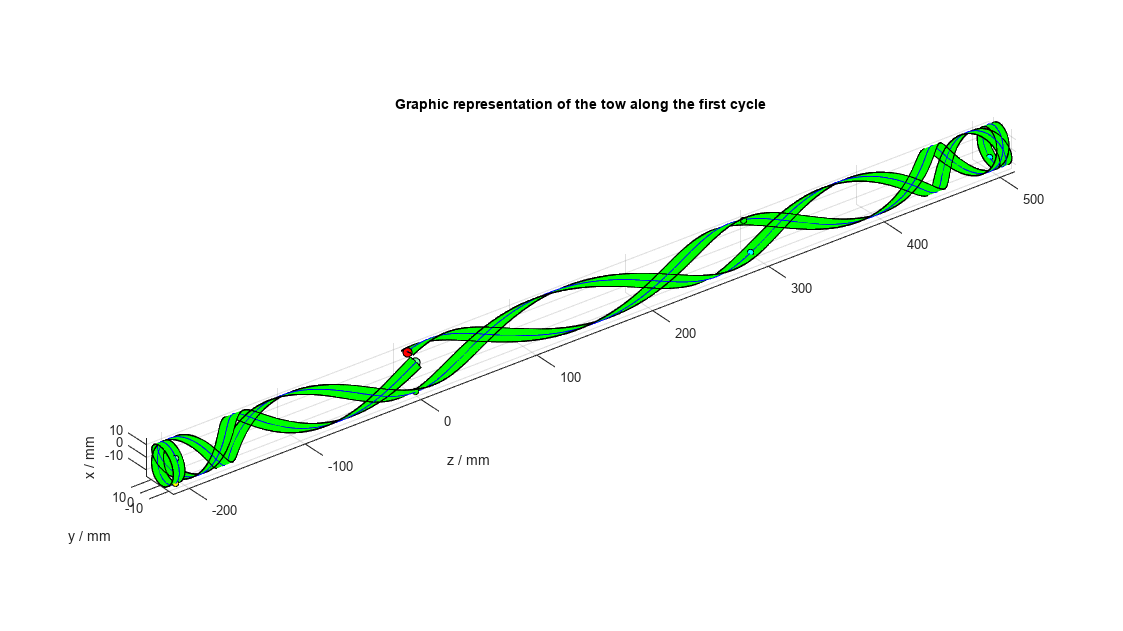

surf(zciclola(:, :), yciclola(:, :), xciclola(:, :), 'FaceColor', 'g', 'EdgeColor', 'none', 'LineStyle', 'none')
hold on;
%plot3(zciclo(1,:),xciclo(1,:),yciclo(1,:),'r','Linewidth',2);
plot3(zciclola(1, :), yciclola(1, :), xciclola(1, :), 'k', 'Linewidth', 0.5);
plot3(zciclola(:, 1), yciclola(:, 1), xciclola(:, 1), 'k', 'Linewidth', 0.5);
plot3(zciclola(:, size(zciclola, 2)), yciclola(:, size(zciclola, 2)), xciclola(:, size(zciclola, 2)), 'k', 'Linewidth', 0.5);
plot3(zciclola((2 * NP + 1), :), yciclola((2 * NP + 1), :), xciclola((2 * NP + 1), :), 'k', 'Linewidth', 0.5);
plot3(zciclola((2 * NP + 2), :), yciclola((2 * NP + 2), :), xciclola((2 * NP + 2), :), 'k', 'Linewidth', 0.5);
plot3(zciclola(2 * (2 * NP + 1), :), yciclola(2 * (2 * NP + 1), :), xciclola(2 * (2 * NP + 1), :), 'k', 'Linewidth', 0.5);
plot3(zciclola((3 * NP + 2), :), yciclola((3 * NP + 2), :), xciclola((3 * NP + 2), :), 'b', 'Linewidth', 0.5);
axis equal
plot3(z(1), y(1), x(1), '-go', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'red', 'MarkerSize', 7)
plot3(z(size(z, 2)), y(size(y, 2)), x(size(x, 2)), '-go', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'green', 'MarkerSize', 5)
plot3(zta(nmeio), yta(nmeio), xta(nmeio), '-go', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'yellow', 'MarkerSize', 5)
plot3(zta(nfimrest), yta(nfimrest), xta(nfimrest), '-go', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'cyan', 'MarkerSize', 5)
plot3(zta(size(zta, 2)), yta(size(yta, 2)), xta(size(xta, 2)), '-go', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'cyan', 'MarkerSize', 5)
plot3(z2(size(z2, 2)), y2(size(y2, 2)), x2(size(x2, 2)), '-go', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'green', 'MarkerSize', 5)
plot3(zta2(nmeio2), yta2(nmeio2), xta2(nmeio2), '-go', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'yellow', 'MarkerSize', 5)
plot3(zta2(nfimrest2), yta2(nfimrest2), xta2(nfimrest2), '-go', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', [.49 1 .63], 'MarkerSize', 5)
plot3(zta2(size(zta2, 2)), yta2(size(yta2, 2)), xta2(size(xta2, 2)), '-go', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', [.49 1 .63], 'MarkerSize', 7)
%title('Mandril e trajectória no mandril do primeiro ciclo')
title('Graphic representation of the tow along the first cycle')
xlabel('z / mm')
ylabel('y / mm')
zlabel('x / mm')
set(gcf, 'color', 'w');
grid on;

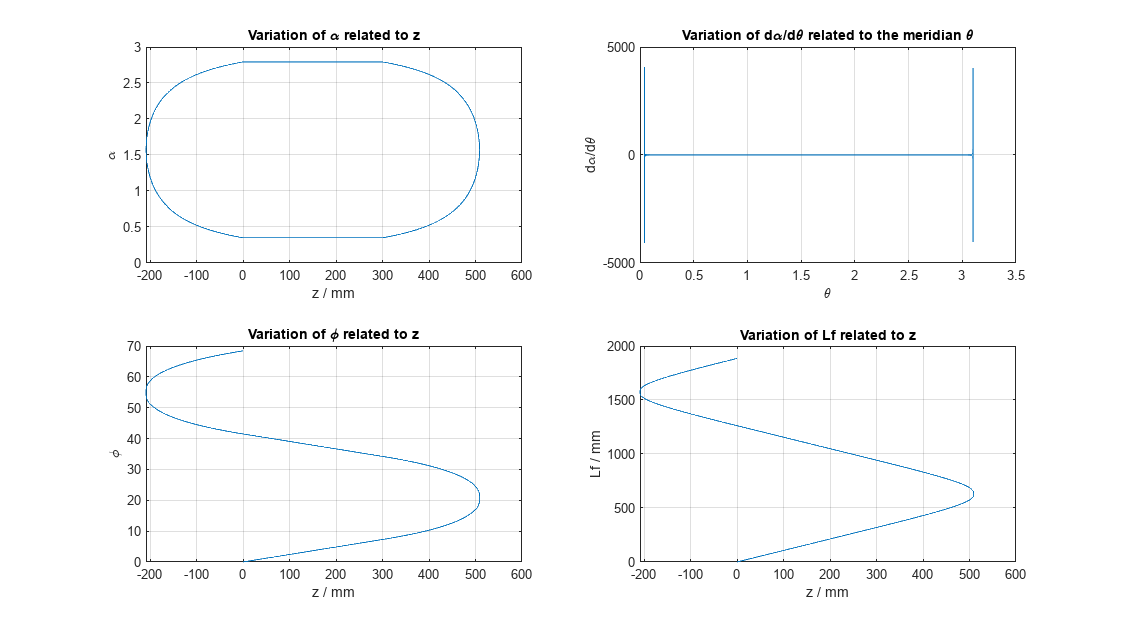

figure ('Name', 'Parameter variation along 1cycle', 'NumberTitle', 'off', 'Position', posfig);
%Alfa em funcao de z
subplot(2, 2, 1)
plot(zciclo(1, :), alfaciclo(1, :))
%%%%%%%%%%%%% Página 43 %%%%%%%%%%%%
title('Variation of \alpha related to z')
xlabel('z / mm')
ylabel('\alpha')
set(gcf, 'color', 'w');
grid on;
%set(gcf,'GridAlpha',0.12);
if rim == rfm
    %dalfadteta em funcao de teta
    subplot(2, 2, 2)
    plot(tetaciclo(1, :), dalfadtetaciclo(1, :))
    title('Variation of d\alpha/d\theta related to the meridian \theta')
    xlabel('\theta')
    ylabel('d\alpha/d\theta')
    set(gcf, 'color', 'w');
    grid on;
    %set(gcf,'GridAlpha',0.1);
else
    %dalfadro em funcao de ro
    subplot(2, 2, 2)
    plot(rociclo(1, :), dalfadrociclo(1, :))
    title('Variation of d\alpha/d\rho related to the meridian \rho')
    xlabel('\rho / mm')
    ylabel('d\alpha/d\rho')
    set(gcf, 'color', 'w');
    grid on;
end

%Phi em funcao de z
subplot(2, 2, 3)
plot(zciclo(1, :), ficiclo(1, :))
title('Variation of \phi related to z')
xlabel('z / mm')
ylabel('\phi')
set(gcf, 'color', 'w');
grid on;
%set(gcf,'GridAlpha',0.07);
%Comprimento da trajectoria (Lf) em funcao de z
subplot(2, 2, 4)
plot(zciclo(1, :), lfciclo(1, :))
title('Variation of Lf related to z')
xlabel('z / mm')
ylabel('Lf / mm')
set(gcf, 'color', 'w');
grid on;

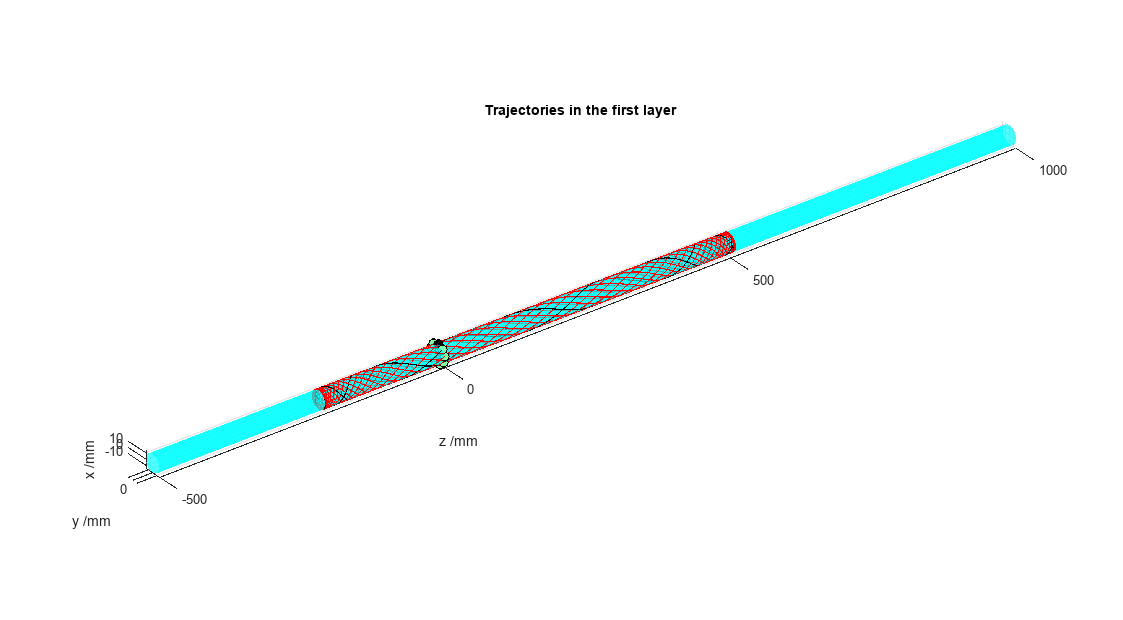

%set(gcf,'GridAlpha',0.05);
%--------------------------------------------------------------------------------------
%
%%%%%%%%%%%%% Página 44 %%%%%%%%%%%%
%--------------------------------------------------------------------------------------
%--------------------------------------------------------------------------------------
% Próximos ciclos
%dficiclo=max(ficiclo(1,:))-(ceil(max(ficiclo(1,:))/(2*pi))*2*pi);
figure ('Name', 'Fibre trajectories in the first layer', 'NumberTitle', 'off', 'Position', posfig);
surf(Z, X, Y, 'FaceColor', 'c', 'FaceAlpha', .7, 'EdgeColor', 'none', 'LineStyle', 'none')
hold on;
plot3(zciclola(NP + 1, :), yciclola(NP + 1, :), xciclola(NP + 1, :), 'k');
axis equal
plot3(zciclola(NP + 1, 1), yciclola(NP + 1, 1), xciclola(NP + 1, 1), '-go', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'k', 'MarkerSize', 7)
title('Trajectories in the first layer')
xlabel('z /mm')
ylabel('y /mm')
zlabel('x /mm')
set(gcf, 'color', 'w');
dficiclo = ficiclo(1, size(ficiclo, 2));

for i = 2:n1
    ficiclo(i, :) = ficiclo(i - 1, :) + dficiclo;
    rociclo(i, :) = rociclo(1, :);
    xciclo(i, :) = rociclo(1, :) .* cos(ficiclo(i, :));
    yciclo(i, :) = rociclo(1, :) .* sin(ficiclo(i, :));
    zciclo(i, :) = zciclo(1, :);
    %surf(zciclola,yciclola,xciclola,'FaceColor','r','EdgeColor','none','LineStyle','none')
    % plot3(zciclo2(i,:),yciclo2(i,:),xciclo2(i,:),'k','Linewidth',0.5);
    % plot3(zciclo3(i,:),yciclo3(i,:),xciclo3(i,:),'k','Linewidth',0.5);
    % plot3(zciclol(6,:),yciclol(6,:),xciclol(6,:),'k','Linewidth',0.5);
    % plot3(zciclol(4,:),yciclol(4,:),xciclol(4,:),'k','Linewidth',0.5);
    plot3(zciclo(i, :), yciclo(i, :), xciclo(i, :), 'r')
    plot3(zciclo(i, 1), yciclo(i, 1), xciclo(i, 1), '-go', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', [.49 1 .63], 'MarkerSize', 7)
end

## Ficheiros exportados

gravartrajectorias = lower(gravartrajectorias);

if gravartrajectorias == 's'
    pathname = fullfile(filepath, '\Resultados');
    %%%%%%%%%%%%% Página 45 %%%%%%%%%%%%
    mkdir(pathname, nomeoutput)
    nomeoutputgeo = [nomeoutput 'geopath.txt'];
    nomeoutputmaq = [nomeoutput 'maqpath.txt'];
    geopathname = fullfile(pathname, '\', nomeoutput, nomeoutputgeo);
    maqpathname = fullfile(pathname, '\', nomeoutput, nomeoutputmaq);
    path = zeros(n1 * size(xciclo, 2), 3);
    maq = zeros(n1 * size(xciclo, 2), 4);

    for j = 1:n1

        for k = 1:size(xciclo, 2)
            path(k + ((j - 1) * size(xciclo, 2)), 1) = xciclo(j, k);
            path(k + ((j - 1) * size(xciclo, 2)), 2) = yciclo(j, k);
            path(k + ((j - 1) * size(xciclo, 2)), 3) = zciclo(j, k);
            maq(k + ((j - 1) * size(xciclo, 2)), 1) = ficiclo(j, k);
            maq(k + ((j - 1) * size(xciclo, 2)), 2) = zciclo(j, k);
            maq(k + ((j - 1) * size(xciclo, 2)), 3) = rociclo(j, k);
            maq(k + ((j - 1) * size(xciclo, 2)), 4) = alfaciclo(1, k);
        end

    end

    % Trajectorias cartesianas (x y z)
    save(geopathname, 'path', '-ascii', '-double', '-tabs')
    % Trajectorias cilindricas/esfericas (fi z ro alfa)
    save(maqpathname, 'maq', '-ascii', '-double', '-tabs')
    %dlmwrite('maqpath.txt',maq,'delimiter','\t','precision','%.6f')
end

Error using mkdir
Acceso denegado.


## CNC

if cnc == 's'
    Bcnc = zeros(1, size(zciclo, 2));
    Bcnc2 = zeros(1, size(zciclo, 2));
    Ycnc = zeros(1, size(zciclo, 2)); %Posição do fim da cabeça (onde passa a fibra). Ycnc ésó usado para coord relativas por isso RefY é aplicado no mpf
    Xcnc = zeros(1, size(zciclo, 2));
    Acnc = ficiclo(1, :);

    for k = 1:size(zciclo, 2)
        %Bcnc(1,k)=alfaciclo(1,k);
        ycnc = rociclo(1, k);
        i = 0;
        rocnc = rociclo(1, k);

        while ycnc < rocnc + D
            i = i + 0.01;
            ycnc = ycnc + i;
            %%%%%%%%%%%%% Página 46 %%%%%%%%%%%%
            dxcnc = ycnc / tan(alfaciclo(1, k));

            if rim == rfm
                rocnc = rim;
                ycnc = rocnc + D;
            else
                rocnc = (((zciclo(1, k) + dxcnc) * dm / lm) + rim - (dm * zim / lm));
            end

        end

        Ycnc(1, k) = ycnc;
        Xcnc(1, k) = zciclo(1, k) + dxcnc;
        Bcnc2(1, k) = atan(rociclo(1, k) * tan(alfaciclo(1, k)) / (Ycnc(1, k) * cos(asin(rociclo(1, k) / Ycnc(1, k)))));

        if Bcnc2(1, k) < 0
            Bcnc2(1, k) = Bcnc2(1, k) + pi;
        end

        Bcnc(1, k) = pi / 2 - Bcnc2(1, k);
    end

    Bcnc = Bcnc .* (180 / pi);
    Acnc = Acnc .* (180 / pi);
    %Coordenadas relativas
    difalfaciclo = zeros(1, size(zciclo, 2) - 1);
    difBcnc = zeros(1, size(zciclo, 2) - 1);
    difYcnc = zeros(1, size(zciclo, 2) - 1);
    difXcnc = zeros(1, size(zciclo, 2) - 1);
    difAcnc = zeros(1, size(zciclo, 2) - 1);

    for k = 1:size(zciclo, 2) - 1
        difalfaciclo(1, k) = alfaciclo(1, k + 1) - alfaciclo(1, k);
        difBcnc(1, k) = Bcnc(1, k + 1) - Bcnc(1, k);
        difXcnc(1, k) = Xcnc(1, k + 1) - Xcnc(1, k);
        difAcnc(1, k) = Acnc(1, k + 1) - Acnc(1, k);
        difYcnc(1, k) = Ycnc(1, k + 1) - Ycnc(1, k);
    end

    t1 = 1:size(difBcnc, 2);
    t2 = 1:size(Bcnc, 2);
    tempo = [];
    VXmaximo = [];
    VYmaximo = [];
    VAmaximo = [];
    VBmaximo = [];
    FeedMTP = [];
    AAreal = [];
    ABreal = [];
    AXreal = [];
    AYreal = [];
    aceleA = 0;
    aceleB = 0;
    aceleX = 0;
    aceleY = 0;
    VXmaximo(1, 1) = 0;
    VYmaximo(1, 1) = 0;
    VAmaximo(1, 1) = 0;
    %%%%%%%%%%%%% Página 47 %%%%%%%%%%%%
    VBmaximo(1, 1) = 0;
    i = 1;
    j = 1;
    contador = 0;
    breaker = 0;
    csb1 = 0;

    while i < (size(difBcnc, 2) + 1) %for i=2:size(difBcnc,2)+1
        i = i + 1;
        j = j + 1;

        if breaker == 0
            difAcnc1(1, j - 1) = difAcnc(1, i - 1);
            difBcnc1(1, j - 1) = difBcnc(1, i - 1);
            difXcnc1(1, j - 1) = difXcnc(1, i - 1);
            difYcnc1(1, j - 1) = difYcnc(1, i - 1);
        else
        end

        breaker = 0;
        tempo(1, j - 1) = difAcnc1(1, j - 1) / (VAmax);
        tempo(2, j - 1) = difBcnc1(1, j - 1) / (VBmax);
        tempo(3, j - 1) = difXcnc1(1, j - 1) / (VXmax);
        tempo(4, j - 1) = difYcnc1(1, j - 1) / (VYmax);
        tempo(5, j - 1) = vel * max(tempo(1:4, j - 1));
        VXmaximo(1, j) = difXcnc1(1, j - 1) / tempo(5, j - 1);
        VYmaximo(1, j) = difYcnc1(1, j - 1) / tempo(5, j - 1);
        VAmaximo(1, j) = difAcnc1(1, j - 1) / tempo(5, j - 1);
        VBmaximo(1, j) = difBcnc1(1, j - 1) / tempo(5, j - 1);
        %Menor tempo de produção (velocidades máximas sempre)
        FeedMTP(1, j - 1) = ((difAcnc1(1, j - 1) ^ 2 + difBcnc1(1, j - 1) ^ 2 + difXcnc1(1, j - 1) ^ 2 + difYcnc1(1, j - 1) ^ 2) ^ 0.5) / (tempo(5, j - 1) / 60);
        %Acelerações
        AAreal(1, j) = abs(VAmaximo(1, j) - VAmaximo(1, j - 1));
        AA1 = VAmaximo(1, j) - VAmaximo(1, j - 1);
        ABreal(1, j) = abs(VBmaximo(1, j) - VBmaximo(1, j - 1));
        AB1 = VBmaximo(1, j) - VBmaximo(1, j - 1);
        AXreal(1, j) = abs(VXmaximo(1, j) - VXmaximo(1, j - 1));
        AX1 = VXmaximo(1, j) - VXmaximo(1, j - 1);
        AYreal(1, j) = abs(VYmaximo(1, j) - VYmaximo(1, j - 1));
        AY1 = VYmaximo(1, j) - VYmaximo(1, j - 1);
        %AA1=1;
        %AB1=1;
        %AX1=1;
        %AY1=1;
        csa = 1;
        csb = 1;

        if difAcnc1(1, j - 1) == 0 && difXcnc1(1, j - 1) == 0 && difYcnc1(1, j - 1) == 0 && difBcnc1(1, j - 1) == 0
            contador = contador + 1;
            difAcnc1(1, j - 1) = difAcnc1(1, j - 1) + difAcnc(1, i);
            %%%%%%%%%%%%% Página 48 %%%%%%%%%%%%
            difBcnc1(1, j - 1) = difBcnc1(1, j - 1) + difBcnc(1, i);
            difXcnc1(1, j - 1) = difXcnc1(1, j - 1) + difXcnc(1, i);
            difYcnc1(1, j - 1) = difYcnc1(1, j - 1) + difYcnc(1, i);
            breaker = 1;
            j = j - 1;
        end

    end

    %Parar maquina
    j = j + 1;
    VXmaximo(1, j) = 0;
    VYmaximo(1, j) = 0;
    VAmaximo(1, j) = 0;
    VBmaximo(1, j) = 0;
    AAreal(1, j) = abs(VAmaximo(1, j) - VAmaximo(1, j - 1));
    AA1 = VAmaximo(1, j) - VAmaximo(1, j - 1);
    ABreal(1, j) = abs(VBmaximo(1, j) - VBmaximo(1, j - 1));
    AXreal(1, j) = abs(VXmaximo(1, j) - VXmaximo(1, j - 1));
    AYreal(1, j) = abs(VYmaximo(1, j) - VYmaximo(1, j - 1));
    %Desaceleração
    pAA = ceil(AAreal(1, j) / AAmax);
    %passos novos
    difAcncpasso = difAcnc1(1, j - 2) / pAA;
    difBcncpasso = difBcnc1(1, j - 2) / pAA;
    difXcncpasso = difXcnc1(1, j - 2) / pAA;
    difYcncpasso = difYcnc1(1, j - 2) / pAA;
    AApasso = AAreal(1, j) / pAA;
    poop2 = j;

    for p = 1:pAA
        difAcnc1(1, j - 2) = difAcncpasso;
        difBcnc1(1, j - 2) = difBcncpasso;
        difXcnc1(1, j - 2) = difXcncpasso;
        difYcnc1(1, j - 2) = difYcncpasso;

        if AA1 < 0
            VAmaximo(1, j) = VAmaximo(1, j - 1) - AApasso;
            tempope = difAcncpasso / VAmaximo(1, j);

            if p == pAA
                break
            end

            tempo(5, j - 2) = tempope;
            VBmaximo(1, j) = difBcncpasso / tempope;
            VXmaximo(1, j) = difXcncpasso / tempope;
            VYmaximo(1, j) = difYcncpasso / tempope;
        else
            VAmaximo(1, j) = VAmaximo(1, j - 1) + AApasso;
            tempope = difAcncpasso / VAmaximo(1, j);

            if p == pAA
                break
            end

            tempo(5, j - 2) = tempope;
            VBmaximo(1, j) = difBcncpasso / tempope;
            %%%%%%%%%%%%% Página 49 %%%%%%%%%%%%
            VXmaximo(1, j) = difXcncpasso / tempope;
            VYmaximo(1, j) = difYcncpasso / tempope;
        end

        AAreal(1, j) = abs(VAmaximo(1, j) - VAmaximo(1, j - 1));
        ABreal(1, j) = abs(VBmaximo(1, j) - VBmaximo(1, j - 1));
        AXreal(1, j) = abs(VXmaximo(1, j) - VXmaximo(1, j - 1));
        AYreal(1, j) = abs(VYmaximo(1, j) - VYmaximo(1, j - 1));
        FeedMTP(1, j - 2) = (difAcnc1(1, j - 2) ^ 2 + difBcnc1(1, j - 2) ^ 2 + difXcnc1(1, j - 2) ^ 2 + difYcnc1(1, j - 2) ^ 2) ^ 0.5 / (tempo(5, j - 2) / 60);

        if p < pAA
            j = j + 1;
        end

    end

    tempo(5, j - 1) = 0;
    %Verificação
    aceleA = 0;
    aceleAa = [];
    a = 0;
    aceleB = 0;
    aceleBa = [];
    btt = 0;
    aceleX = 0;
    aceleXa = [];
    x = 0;
    aceleY = 0;
    aceleYa = [];
    y = 0;
    velociA = 0;
    velociB = 0;
    velociX = 0;
    velociY = 0;
    ACNC = zeros(1, size(difAcnc1, 2) + 1);
    BCNC = zeros(1, size(difAcnc1, 2) + 1);
    XCNC = zeros(1, size(difAcnc1, 2) + 1);
    YCNC = zeros(1, size(difAcnc1, 2) + 1);
    ACNC(1, 1) = Acnc(1, 1);
    BCNC(1, 1) = Bcnc(1, 1);
    XCNC(1, 1) = Xcnc(1, 1);
    YCNC(1, 1) = Ycnc(1, 1);
    velocicheckA = zeros(1, size(difAcnc1, 2) + 1);
    velocicheckB = zeros(1, size(difAcnc1, 2) + 1);
    velocicheckX = zeros(1, size(difAcnc1, 2) + 1);
    velocicheckY = zeros(1, size(difAcnc1, 2) + 1);
    velocicheckA(1, 1) = 0;
    velocicheckB(1, 1) = 0;
    velocicheckX(1, 1) = 0;
    velocicheckY(1, 1) = 0;
    acelecheckA = zeros(1, size(difAcnc1, 2));
    acelecheckB = zeros(1, size(difAcnc1, 2));
    acelecheckX = zeros(1, size(difAcnc1, 2));
    %%%%%%%%%%%%% Página 50 %%%%%%%%%%%%
    acelecheckY = zeros(1, size(difAcnc1, 2));
    tempoplot = zeros(1, size(difAcnc1, 2) + 1);
    tempoplot(1, 1) = 0;

    for j = 2:size(difAcnc1, 2) + 1
        ACNC(1, j) = ACNC(1, j - 1) + difAcnc1(1, j - 1);
        BCNC(1, j) = BCNC(1, j - 1) + difBcnc1(1, j - 1);
        XCNC(1, j) = XCNC(1, j - 1) + difXcnc1(1, j - 1);
        YCNC(1, j) = YCNC(1, j - 1) + difYcnc1(1, j - 1);
        tempoplot(1, j) = tempoplot(1, j - 1) + tempo(5, j - 1);
        velocicheckA(1, j) = difAcnc1(1, j - 1) / tempo(5, j - 1);
        velocicheckB(1, j) = difBcnc1(1, j - 1) / tempo(5, j - 1);
        velocicheckX(1, j) = difXcnc1(1, j - 1) / tempo(5, j - 1);
        velocicheckY(1, j) = difYcnc1(1, j - 1) / tempo(5, j - 1);
        acelecheckA(1, j - 1) = abs(velocicheckA(1, j) - velocicheckA(1, j - 1));
        acelecheckB(1, j - 1) = abs(velocicheckB(1, j) - velocicheckB(1, j - 1));
        acelecheckX(1, j - 1) = abs(velocicheckX(1, j) - velocicheckX(1, j - 1));
        acelecheckY(1, j - 1) = abs(velocicheckY(1, j) - velocicheckY(1, j - 1));
    end

    j = j + 1;
    velocicheckA(1, j) = 0;
    velocicheckB(1, j) = 0;
    velocicheckX(1, j) = 0;
    velocicheckY(1, j) = 0;
    acelecheckA(1, j - 1) = abs(velocicheckA(1, j) - velocicheckA(1, j - 1));
    acelecheckB(1, j - 1) = abs(velocicheckB(1, j) - velocicheckB(1, j - 1));
    acelecheckX(1, j - 1) = abs(velocicheckX(1, j) - velocicheckX(1, j - 1));
    acelecheckY(1, j - 1) = abs(velocicheckY(1, j) - velocicheckY(1, j - 1));
    t4 = 1:size(velocicheckA, 2);
    t3 = 1:size(ACNC, 2);

    for j = 1:size(acelecheckA, 2)

        if acelecheckA(1, j) > AAmax
            aceleA = aceleA + 1;
            a = a + 1;
            aceleAa(1, a) = j;
        end

        if acelecheckB(1, j) > ABmax
            aceleB = aceleB + 1;
            btt = btt + 1;
            aceleBa(1, btt) = j;
        end

        if acelecheckX(1, j) > AXmax
            aceleX = aceleX + 1;
            x = x + 1;
            aceleXa(1, x) = j;
        end

        if acelecheckY(1, j) > AYmax
            aceleY = aceleY + 1;
            y = y + 1;
            aceleYa(1, y) = j;
        end

        if VAmaximo(1, j) > VAmax
            %%%%%%%%%%%%% Página 51 %%%%%%%%%%%%
            velociA = velociA + 1;
        end

        if VBmaximo(1, j) > VBmax
            velociB = velociB + 1;
        end

        if VXmaximo(1, j) > VXmax
            velociX = velociX + 1;
        end

        if VYmaximo(1, j) > VYmax
            velociY = velociY + 1;
        end

    end

    %Fazer os ficheiros
    gravarcnc = lower(gravarcnc);

    if gravarcnc == 's'
        nomeoutputspf = [nomeoutput 'CNCciclo.spf'];
        nomeoutputspf1 = [nomeoutput 'CNCciclo'];
        nomeoutputmpf = [nomeoutput 'CNCmain.mpf'];
        cncspf = fullfile(pathname, '\', nomeoutput, nomeoutputspf);
        cncmpf = fullfile(pathname, '\', nomeoutput, nomeoutputmpf);
        Y0 = RefY + rfm + D; %rfm pois é o maior raio do mandril
        Y1 = RefY + rociclo(1, 1) + D;
        F0 = 5000;
        X0 = Xmin + zi - zim;
        % Ficheiro CNC .mpf
        fileID = fopen(cncmpf, 'w');
        fprintf(fileID, '%4s %4s\r\n', ';Pathwind', 'INEGI');
        fprintf(fileID, ';%s\r\n', datestr(clock));
        fprintf(fileID, 'M00\r\nN010 G01 G64 G90 G94 Y%.3f F%.3f\r\nN020 X%.3f B%.3f C0Z0\r\nN030 Y%.3f\r\nM00\r\nN040 %s P%d\r\nN050 M30\r\n', Y0, F0, X0, alfainicio, Y1, nomeoutputspf1, n1);
        fclose(fileID);
        %Feedmax=zeros(1,size(difAcnc,2));
        %Feedmax(1,1)=((difAcnc(1,1)^2+difBcnc(1,1)^2+difYcnc(1,1)^2+difYcnc(1,1)^2)^0.5)/tempo(5,1); %tempo/60
        % Ficheiro CNC .spf
        fileID = fopen(cncspf, 'w');
        fprintf(fileID, 'N010 G01 G91 G64 G94 A%.3f X%.3f Y%.3f B%.3f F%.3f\r\n', difAcnc(1, 1), difXcnc(1, 1), difYcnc(1, 1), difBcnc(1, 1), FeedMTP(1, 1));

        for j = 2:size(difAcnc1, 2) - 1
            %Feedmax(1,j)=((difAcnc(1,j)^2+difBcnc(1,j)^2+difYcnc(1,j)^2+difYcnc(1,j)^2)^0.5)/(tempo(5,j)); %tempo/60?
            if difAcnc1(1, j) == 0 && difBcnc1(1, j) == 0 && difXcnc1(1, j) == 0 && difYcnc1(1, j) == 0
            else
                fprintf(fileID, 'N0%i0 A%.3f X%.3f Y%.3f B%.3f F%.3f\r\n', j, difAcnc1(1, j), difXcnc1(1, j), difYcnc1(1, j), difBcnc1(1, j), FeedMTP(1, j));
            end

        end

        %%%%%%%%%%%%% Página 52 %%%%%%%%%%%%
        fprintf(fileID, 'RET\r\n');
        fclose(fileID);
    end

    figure ('Name', 'Machine axes movement related to vectorposition', 'NumberTitle', 'off', 'Position', posfig);
    %B em funcao de t
    subplot(2, 2, 1)
    plot(t3, BCNC)
    title('Movement of axis B')
    xlabel('')
    ylabel('B / º')
    set(gcf, 'color', 'w');
    grid on;
    %A em funcao de t
    subplot(2, 2, 2)
    plot(t3, ACNC)
    title('Movement of axis A')
    xlabel('')
    ylabel('A / º')
    set(gcf, 'color', 'w');
    grid on;
    %X em funcao de t
    subplot(2, 2, 3)
    plot(t3, XCNC)
    title('Movement of axis X')
    xlabel('')
    ylabel('X / mm')
    set(gcf, 'color', 'w');
    grid on;
    %Y em funcao de t
    subplot(2, 2, 4)
    plot(t3, YCNC);
    title('Movement of axis Y')
    xlabel('')
    ylabel('Y / mm')
    set(gcf, 'color', 'w');
    grid on;
    figure ('Name', 'Machine axis movement related to time', 'NumberTitle', 'off', 'Position', posfig);
    %B em funcao de t
    subplot(2, 2, 1)
    plot(tempoplot, BCNC)
    title('Movement of axis B')
    xlabel('t / s')
    ylabel('B / º')
    set(gcf, 'color', 'w');
    %%%%%%%%%%%%% Página 53 %%%%%%%%%%%%
    grid on;
    %A em funcao de t
    subplot(2, 2, 2)
    plot(tempoplot, ACNC)
    title('Movement of axis A')
    xlabel('t / s')
    ylabel('A / º')
    set(gcf, 'color', 'w');
    grid on;
    %X em funcao de t
    subplot(2, 2, 3)
    plot(tempoplot, XCNC)
    title('Movement of axis X')
    xlabel('t / s')
    ylabel('X / mm')
    set(gcf, 'color', 'w');
    grid on;
    %Y em funcao de t
    subplot(2, 2, 4)
    plot(tempoplot, YCNC);
    title('Movement of axis Y')
    xlabel('t / s')
    ylabel('Y / mm')
    set(gcf, 'color', 'w');
    grid on;
    figure ('Name', 'Velocidade dos eixos da máquina em função dotempo', 'NumberTitle', 'off', 'Position', posfig);
    tempoplot1 = zeros(1, size(tempoplot, 2) + 1);
    tempoplot1(1, 1:size(tempoplot, 2)) = tempoplot(1, :);
    tempoplot1(1, size(tempoplot1, 2)) = tempoplot1(1, size(tempoplot1, 2) - 1) + 0.0001;
    %B em funcao de t
    subplot(2, 2, 1)
    plot(tempoplot1, velocicheckB)
    title('Velocity of axis B')
    xlabel('t / s')
    ylabel('VB / º/s')
    set(gcf, 'color', 'w');
    grid on;
    %A em funcao de t
    subplot(2, 2, 2)
    plot(tempoplot1, velocicheckA)
    title('Velocity of axis A')
    xlabel('t / s')
    ylabel('VA / º/s')
    set(gcf, 'color', 'w');
    grid on;
    %X em funcao de t
    subplot(2, 2, 3)
    %%%%%%%%%%%%% Página 54 %%%%%%%%%%%%
    plot(tempoplot1, velocicheckX)
    title('Velocity of axis X')
    xlabel('t / s')
    ylabel('VX / mm/s')
    set(gcf, 'color', 'w');
    grid on;
    %Y em funcao de t
    subplot(2, 2, 4)
    plot(tempoplot1, velocicheckY);
    title('Velocity of axis Y')
    xlabel('t / s')
    ylabel('VY / mm/s')
    set(gcf, 'color', 'w');
    grid on;
end

## Sobreposições

switch lower(sobre)
    case {'sobreposiçao3', 'sobreposição3'}
        disp('Sobreposição')
        %criar matriz para ordenar por z
        zsobre = zeros(size(zciclo, 2) * size(zciclo, 1), 1);
        alfasobre = zeros(size(zciclo, 2) * size(zciclo, 1), 1);
        fisobre = zeros(size(zciclo, 2) * size(zciclo, 1), 1);
        rosobre = zeros(size(zciclo, 2) * size(zciclo, 1), 1);
        xsobre = zeros(size(zciclo, 2) * size(zciclo, 1), 1);
        ysobre = zeros(size(zciclo, 2) * size(zciclo, 1), 1);
        numeracaomatriz = zeros(size(zciclo, 2) * size(zciclo, 1), 1);
        contsobre = 0;

        for j = 1:size(zciclo, 1)

            for i = 1:size(zciclo, 2)
                contsobre = contsobre + 1;
                zsobre(contsobre, 1) = zciclo(j, i);
                alfasobre(contsobre, 1) = alfaciclo(1, i);
                fisobre(contsobre, 1) = ficiclo(j, i);
                rosobre(contsobre, 1) = rociclo(j, i);
                xsobre(contsobre, 1) = xciclo(j, i);
                ysobre(contsobre, 1) = yciclo(j, i);
                numeracaomatriz(contsobre, 1) = contsobre;
            end

        end

        %Novo vector fi - errado!!!!!
        finovo1 = zeros(size(fisobre));

        for i = 1:size(fisobre, 1)
            finovo1(i, 1) = fisobre(i, 1);

            while finovo1(i, 1) > 2 * pi
                finovo1(i, 1) = finovo1(i, 1) - 2 * pi;
                %%%%%%%%%%%%% Página 55 %%%%%%%%%%%%
            end

        end

        %matriz com todos os ciclos
        matrizsobre = [zsobre numeracaomatriz finovo1 rosobre alfasobre xsobre ysobre];
        %matriz ordenada
        matrizsobreordenada = sortrows(matrizsobre);
    case {'coco'}
        %restantes paths para a matriz ordenada
        dfilargurasobre(:, 1) = (b ./ (2 .* rosobre(:, 1))) .* (cos(alfasobre(:, 1)));
        dzlargurasobre(:, 1) = (b / 2) .* sin(alfasobre(:, 1)) .* cos(tau);
        fisobrela = zeros(2 * NP + 1, size(fisobre, 1));
        zsobrela = zeros(4 * NP + 2, size(fisobre, 1));
        rosobrela = zeros(2 * NP + 1, size(fisobre, 1));

        for i = 1:(2 * NP + 1)
            fisobrela(i, :) = finovo1(1, :) - dfilargura(1, :) + (i - 1) * (dfilargura(1, :) / NP);
            zsobrela(i, :) = zciclo(1, :) + dzlargura(1, :) - (i - 1) * (dzlargura(1, :) / NP);
            rosobrela(i, :) = ((zciclola(i, :) * dm / lm) + rim - (dm * zim / lm));
        end

        firealla = zeros(size(ficiclo, 1), (2 * NP + 1));

        for l = 1:(2 * NP + 1)
            firealla(:, l) = fireal - dfilargura(1, k) + (l - 1) * (dfilargura(1, k) / NP);
        end

        %T=[cos(alfaciclo(1,i)) sin(alfaciclo(1,i));-sin(alfaciclo(1,i)) cos(alfaciclo(1,i))];
        for k = 1:size(zsobre, 1)
            i = k - 1;

            if i > 0 && i <= size(zsobre, 1)

                while abs(matrizsobreordenada(i, 1) - matrizsobreordenada(k, 1)) / cos(tau) < b
                    dfi = abs(matrizsobreordenada(i, 2) - matrizsobreordenada(k, 2));

                    if dfi > pi
                        dfi = 2 * pi - dfi;
                    end

                    if dfi < (b / matrizsobreordenada(k, 3))
                    end

                    i = i - 1;

                    if i <= 0
                        break
                    end

                    if i > size(zsobre, 1)
                        break
                    end

                end

            end

            %%%%%%%%%%%%% Página 56 %%%%%%%%%%%%
            j = k + 1;

            if j > 0 && j <= size(zsobre, 1)

                while abs(matrizsobreordenada(j, 1) - matrizsobreordenada(k, 1)) / cos(tau) < b
                    dfi = abs(matrizsobreordenada(j, 2) - matrizsobreordenada(k, 2));

                    if dfi > pi
                        dfi = 2 * pi - dfi;
                    end

                    j = j + 1;

                    if j <= 0
                        break
                    end

                    if j > size(zsobre, 1)
                        break
                    end

                end

            end

        end

    case {'sobreposiçao1', 'sobreposiçao2', 'sobreposição1', 'sobreposição2'}

        if lower(sobre) == 'sobreposiçao1'
            disp('Sobreposição do primeiro ciclo')
        else
            disp('Sobreposição')
        end

        %Novo vector fi
        finovo1 = zeros(n1, size(ficiclo, 2));

        for i = 1:size(ficiclo, 2)
            finovo1(1, i) = ficiclo(1, i);

            while finovo1(1, i) > 2 * pi
                finovo1(1, i) = finovo1(1, i) - 2 * pi;
            end

        end

        % Sobreposição
        for k = 1:size(zciclo, 2)
            i = 1;

            while ficiclo(1, i) < (ficiclo(1, k) - 2 * pi)

                if abs(zciclo(1, i) - zciclo(1, k)) / cos(tau) < b

                    if abs(finovo1(1, i) - finovo1(1, k)) < (b / rociclo(1, i))
                        finovo = ficiclo(1, k);
                        fireal = ficiclo(1, k);
                        dfireal = abs(ficiclo(1, i) - finovo);

                        while finovo > 0
                            finovo = finovo - 2 * pi;
                            %%%%%%%%%%%%% Página 57 %%%%%%%%%%%%
                            dfi1 = abs(ficiclo(1, i) - finovo);

                            if dfi1 < dfireal
                                fireal = finovo;
                                dfireal = dfi1;
                            end

                        end

                        firealla = zeros((2 * NP + 1), 1);

                        for l = 1:(2 * NP + 1)
                            firealla(l, 1) = fireal - dfilargura(1, k) + (l - 1) * (dfilargura(1, k) / NP);
                        end

                        T = [cos(alfaciclo(1, i)) sin(alfaciclo(1, i)); -sin(alfaciclo(1, i)) cos(alfaciclo(1, i))];
                        % Multiplas linhas
                        for l = 1:(2 * NP + 1)

                            for m = 1:(2 * NP + 1)

                                if rociclola(l, k) > rociclola(m, i)
                                    distla(m, l) = (((zciclola(l, k) - zciclola(m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)) ^ 2) ^ 0.5;
                                    distlav(m, l, :) = [(zciclola(l, k) - zciclola(m, i)) / cos(tau) (firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)];
                                    distlav1 = [(zciclola(l, k) - zciclola(m, i)) / cos(tau); (firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)];
                                else
                                    distla(m, l) = (((zciclola(l, k) - zciclola(m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)) ^ 2) ^ 0.5;
                                    distlav(m, l, :) = [(zciclola(l, k) - zciclola(m, i)) / cos(tau) (firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)];
                                    distlav1 = [(zciclola(l, k) - zciclola(m, i)) / cos(tau); (firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)];
                                end

                                distlava1 = T * distlav1;
                                distlava(m, l) = distlava1(2, 1);
                            end

                        end

                        for l = 1:(2 * NP + 1)

                            if abs(distla(1, l)) < b && abs(distla(2 * NP + 1, l)) < b
                                minimo = abs(distlava(1, l));
                                posi = 1;

                                for m = 1:(2 * NP + 1)
                                    minimo1 = abs(distlava(m, l));

                                    if minimo1 < minimo
                                        minimo = minimo1;
                                        posi = m;
                                    end

                                end

                                if posi ~= 2 * NP + 1 && posi ~= 1
                                    %%%%%%%%%%%%% Página 58 %%%%%%%%%%%%
                                    if abs(distlava(posi - 1, l)) <= abs(distlava(posi + 1, l))
                                        rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                    else
                                        rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                    end

                                else

                                    if posi == 2 * NP + 1
                                        rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                    else
                                        rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                    end

                                end

                            end

                        end

                    else

                        if abs(finovo1(1, i) - finovo1(1, k)) > (2 * pi - (b / rociclo(1, i)))
                            finovo = ficiclo(1, k);
                            fireal = ficiclo(1, k);
                            dfireal = abs(ficiclo(1, i) - finovo);

                            while finovo > 0
                                finovo = finovo - 2 * pi;
                                dfi1 = abs(ficiclo(1, i) - finovo);

                                if dfi1 < dfireal
                                    fireal = finovo;
                                    dfireal = dfi1;
                                end

                            end

                            firealla = zeros((2 * NP + 1), 1);

                            for l = 1:(2 * NP + 1)
                                firealla(l, 1) = fireal - dfilargura(1, k) + (l - 1) * (dfilargura(1, k) / NP);
                            end

                            T = [cos(alfaciclo(1, i)) sin(alfaciclo(1, i)); -sin(alfaciclo(1, i)) cos(alfaciclo(1, i))];
                            % Multiplas linhas
                            for l = 1:(2 * NP + 1)
                                %%%%%%%%%%%%% Página 59 %%%%%%%%%%%%
                                for m = 1:(2 * NP + 1)

                                    if rociclola(l, k) > rociclola(m, i)
                                        distla(m, l) = (((zciclola(l, k) - zciclola(m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)) ^ 2) ^ 0.5;
                                        distlav(m, l, :) = [(zciclola(l, k) - zciclola(m, i)) / cos(tau) (firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)];
                                        distlav1 = [(zciclola(l, k) - zciclola(m, i)) / cos(tau); (firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)];
                                    else
                                        distla(m, l) = (((zciclola(l, k) - zciclola(m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)) ^ 2) ^ 0.5;
                                        distlav(m, l, :) = [(zciclola(l, k) - zciclola(m, i)) / cos(tau) (firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)];
                                        distlav1 = [(zciclola(l, k) - zciclola(m, i)) / cos(tau); (firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)];
                                    end

                                    distlava1 = T * distlav1;
                                    distlava(m, l) = distlava1(2, 1);
                                end

                            end

                            for l = 1:(2 * NP + 1)

                                if abs(distla(1, l)) < b && abs(distla(2 * NP + 1, l)) < b
                                    minimo = abs(distlava(1, l));
                                    posi = 1;

                                    for m = 1:(2 * NP + 1)
                                        minimo1 = abs(distlava(m, l));

                                        if minimo1 < minimo
                                            minimo = minimo1;
                                            posi = m;
                                        end

                                    end

                                    if posi ~= 2 * NP + 1 && posi ~= 1

                                        if abs(distlava(posi - 1, l)) <= abs(distlava(posi + 1, l))
                                            rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                            zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                        else
                                            rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                            zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                        end

                                    else

                                        if posi == 2 * NP + 1
                                            rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                            zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                            %%%%%%%%%%%%% Página 60 %%%%%%%%%%%%
                                        else
                                            rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                            zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                        end

                                    end

                                end

                            end

                        end

                    end

                end

                i = i + 1;
            end

        end

        % Cartesianas multiplas linhas
        xciclola = zeros(4 * NP + 2, size(ficiclola, 2));
        yciclola = zeros(4 * NP + 2, size(ficiclola, 2));

        for n = 1:2 * NP + 1
            xciclola(n, :) = rociclola(n, :) .* cos(ficiclola(n, :));
            yciclola(n, :) = rociclola(n, :) .* sin(ficiclola(n, :));
        end

        c = 1;

        for n = 2 * NP + 2:2 * (2 * NP + 1)
            xciclola(n, :) = (rociclola((2 * NP + 2 - c), :) + esp / cos(tau)) .* cos(ficiclola((2 * NP + 2 - c), :));
            yciclola(n, :) = (rociclola((2 * NP + 2 - c), :) + esp / cos(tau)) .* sin(ficiclola((2 * NP + 2 - c), :));
            zciclola(n, :) = zciclola((2 * NP + 2 - c), :) - esp * sin(tau);
            c = c + 1;
        end

        rociclolae = [];
        ficiclolae = [];
        zciclolae = [];
        rociclolae(1, :, :) = rociclola(:, :);
        ficiclolae(1, :, :) = ficiclola(:, :);
        zciclolae(1, :, :) = zciclola(:, :);
        %Plot Mandril e trajectoria com multiplas linhas
        figure ('Name', 'Primeira camada', 'NumberTitle', 'off', 'Position', posfig); surf(Z, X, Y, 'FaceColor', 'c', 'FaceAlpha', .7, 'EdgeColor', 'none', 'LineStyle', 'none')
        hold on;
        surf(zciclola(:, :), yciclola(:, :), xciclola(:, :), 'FaceColor', 'r', 'EdgeColor', 'none', 'LineStyle', 'none')
        %hold on;
        %plot3(zciclo(1,:),xciclo(1,:),yciclo(1,:),'r','Linewidth',2);
        plot3(zciclola(1, :), yciclola(1, :), xciclola(1, :), 'k', 'Linewidth', 0.5);
        plot3(zciclola((2 * NP + 1), :), yciclola((2 * NP + 1), :), xciclola((2 * NP + 1), :), 'k', 'Linewidth', 0.5);
        %%%%%%%%%%%%% Página 61 %%%%%%%%%%%%
        plot3(zciclola((2 * NP + 2), :), yciclola((2 * NP + 2), :), xciclola((2 * NP + 2), :), 'k', 'Linewidth', 0.5);
        plot3(zciclola(2 * (2 * NP + 1), :), yciclola(2 * (2 * NP + 1), :), xciclola(2 * (2 * NP + 1), :), 'k', 'Linewidth', 0.5);
        plot3(zciclola((3 * NP + 2), :), yciclola((3 * NP + 2), :), xciclola((3 * NP + 2), :), 'b', 'Linewidth', 0.5);
        axis equal
        title('Primeira camada')
        xlabel('z')
        ylabel('y')
        zlabel('x')
        set(gcf, 'color', 'w');
        grid on;

        switch lower(sobre)
            case {'sobreposiçao2', 'sobreposição2'}
                disp('Sobreposição de todos os ciclos primeira camada')
                % Todos os ciclos
                for o = 2:n1
                    % pegar nas trajectórias já geradas e adicionar a largura/espessura
                    % (isto pode ser lá em cima, só não é representado)
                    %verificar se tem paths por baixo
                    % Restantes Paths - NP
                    ficiclola = zeros(2 * NP + 1, size(ficiclo, 2));
                    zciclola = zeros(4 * NP + 2, size(ficiclola, 2));
                    rociclola = zeros(2 * NP + 1, size(ficiclo, 2));

                    for i = 1:(2 * NP + 1)
                        ficiclola(i, :) = ficiclo(o, :) - dfilargura(1, :) + (i - 1) * (dfilargura(1, :) / NP);
                        zciclola(i, :) = zciclo(o, :) + dzlargura(1, :) - (i - 1) * (dzlargura(1, :) / NP);
                        rociclola(i, :) = ((zciclola(i, :) * dm / lm) + rim - (dm * zim / lm));
                    end

                    %Sobreposição ciclos anteriores
                    %Novo vector fi
                    for i = 1:size(ficiclo, 2)
                        finovo1(1, i) = ficiclo(1, i);

                        while finovo1(1, i) > 2 * pi
                            finovo1(1, i) = finovo1(1, i) - 2 * pi;
                        end

                    end

                    for g = 1:o - 1

                        for k = 1:size(zciclo, 2) %ciclo 'o'
                            %i=1;
                            for i = 1:size(zciclo, 2) %while ficiclo(1,i)<(ficiclo(1,k)-2*pi) %ciclo 'g'

                                if abs(zciclo(g, i) - zciclo(o, k)) / cos(tau) < b

                                    if abs(finovo1(g, i) - finovo1(o, k)) < (b / rociclolae(g, NP + 1, i))
                                        %%%%%%%%%%%%% Página 62 %%%%%%%%%%%%
                                        finovo = ficiclo(o, k);
                                        fireal = ficiclo(o, k);
                                        dfireal = abs(ficiclo(g, i) - finovo);

                                        while finovo > 0
                                            finovo = finovo - 2 * pi;
                                            dfi1 = abs(ficiclo(g, i) - finovo);

                                            if dfi1 < dfireal
                                                fireal = finovo;
                                                dfireal = dfi1;
                                            end

                                        end

                                        firealla = zeros((2 * NP + 1), 1);

                                        for l = 1:(2 * NP + 1)
                                            firealla(l, 1) = fireal - dfilargura(1, k) + (l - 1) * (dfilargura(1, k) / NP);
                                        end

                                        T = [cos(alfaciclo(1, i)) sin(alfaciclo(1, i)); -sin(alfaciclo(1, i)) cos(alfaciclo(1, i))];
                                        % Multiplas linhas
                                        for l = 1:(2 * NP + 1)

                                            for m = 1:(2 * NP + 1)

                                                if rociclola(l, k) > rociclolae(g, m, i)
                                                    distla(m, l) = (((zciclola(l, k) - zciclolae(g, m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclolae(g, m, i)) * rociclola(l, k)) ^ 2) ^ 0.5;
                                                    distlav(m, l, :) = [(zciclola(l, k) - zciclolae(g, m, i)) / cos(tau) (firealla(l, 1) - ficiclolae(g, m, i)) * rociclola(l, k)];
                                                    distlav1 = [(zciclola(l, k) - zciclolae(g, m, i)) / cos(tau); (firealla(l, 1) - ficiclolae(g, m, i)) * rociclola(l, k)];
                                                else
                                                    distla(m, l) = (((zciclola(l, k) - zciclolae(g, m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclolae(g, m, i)) * rociclolae(g, m, i)) ^ 2) ^ 0.5;
                                                    distlav(m, l, :) = [(zciclola(l, k) - zciclolae(g, m, i)) / cos(tau) (firealla(l, 1) - ficiclolae(g, m, i)) * rociclolae(g, m, i)];
                                                    distlav1 = [(zciclola(l, k) - zciclolae(g, m, i)) / cos(tau); (firealla(l, 1) - ficiclolae(g, m, i)) * rociclolae(g, m, i)];
                                                end

                                                distlava1 = T * distlav1;
                                                distlava(m, l) = distlava1(2, 1);
                                            end

                                        end

                                        for l = 1:(2 * NP + 1)

                                            if abs(distla(1, l)) < b && abs(distla(2 * NP + 1, l)) < b
                                                minimo = abs(distlava(1, l));
                                                posi = 1;

                                                for m = 1:(2 * NP + 1)
                                                    minimo1 = abs(distlava(m, l));
                                                    %%%%%%%%%%%%% Página 63 %%%%%%%%%%%%
                                                    if minimo1 < minimo
                                                        minimo = minimo1;
                                                        posi = m;
                                                    end

                                                end

                                                if posi ~= 2 * NP + 1 && posi ~= 1

                                                    if abs(distlava(posi - 1, l)) <= abs(distlava(posi + 1, l))
                                                        rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclolae(g, posi, i) + abs(distlava(posi, l)) * rociclolae(g, posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                    else
                                                        rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclolae(g, posi, i) + abs(distlava(posi, l)) * rociclolae(g, posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                    end

                                                else

                                                    if posi == 2 * NP + 1
                                                        rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclolae(g, posi, i) + abs(distlava(posi, l)) * rociclolae(g, posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                    else
                                                        rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclolae(g, posi, i) + abs(distlava(posi, l)) * rociclolae(g, posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                    end

                                                end

                                            end

                                        end

                                    else

                                        if abs(finovo1(g, i) - finovo1(o, k)) > (2 * pi - (b / rociclolae(g, 1, i)))
                                            finovo = ficiclo(o, k);
                                            fireal = ficiclo(o, k);
                                            dfireal = abs(ficiclo(g, i) - finovo);

                                            while finovo > 0
                                                finovo = finovo - 2 * pi;
                                                dfi1 = abs(ficiclo(g, i) - finovo);

                                                if dfi1 < dfireal
                                                    fireal = finovo;
                                                    dfireal = dfi1;
                                                end

                                            end

                                            firealla = zeros((2 * NP + 1), 1);
                                            %%%%%%%%%%%%% Página 64 %%%%%%%%%%%%
                                            for l = 1:(2 * NP + 1)
                                                firealla(l, 1) = fireal - dfilargura(1, k) + (l - 1) * (dfilargura(1, k) / NP);
                                            end

                                            T = [cos(alfaciclo(1, i)) sin(alfaciclo(1, i)); -sin
                                               (alfaciclo(1, i)) cos(alfaciclo(1, i))];
                                            % Multiplas linhas
                                            for l = 1:(2 * NP + 1)

                                                for m = 1:(2 * NP + 1)

                                                    if rociclola(l, k) > rociclolae(g, m, i)
                                                        distla(m, l) = (((zciclola(l, k) - zciclolae(g, m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclolae(g, m, i)) * rociclola(l, k)) ^ 2) ^ 0.5;
                                                        distlav(m, l, :) = [(zciclola(l, k) - zciclolae(g, m, i)) / cos(tau) (firealla(l, 1) - ficiclolae(g, m, i)) * rociclola(l, k)];
                                                        distlav1 = [(zciclola(l, k) - zciclolae(g, m, i)) / cos(tau); (firealla(l, 1) - ficiclolae(g, m, i)) * rociclola(l, k)];
                                                    else
                                                        distla(m, l) = (((zciclola(l, k) - zciclolae(g, m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclolae(g, m, i)) * rociclolae(g, m, i)) ^ 2) ^ 0.5;
                                                        distlav(m, l, :) = [(zciclola(l, k) - zciclolae(g, m, i)) / cos(tau) (firealla(l, 1) - ficiclolae(g, m, i)) * rociclolae(g, m, i)];
                                                        distlav1 = [(zciclola(l, k) - zciclolae(g, m, i)) / cos(tau); (firealla(l, 1) - ficiclolae(g, m, i)) * rociclolae(g, m, i)];
                                                    end

                                                    distlava1 = T * distlav1;
                                                    distlava(m, l) = distlava1(2, 1);
                                                end

                                            end

                                            for l = 1:(2 * NP + 1)

                                                if abs(distla(1, l)) < b && abs(distla(2 * NP + 1, l)) < b
                                                    minimo = abs(distlava(1, l));
                                                    posi = 1;

                                                    for m = 1:(2 * NP + 1)
                                                        minimo1 = abs(distlava(m, l));

                                                        if minimo1 < minimo
                                                            minimo = minimo1;
                                                            posi = m;
                                                        end

                                                    end

                                                    if posi ~= 2 * NP + 1 && posi ~= 1

                                                        if abs(distlava(posi - 1, l)) <= abs(distlava(posi + 1, l))
                                                            rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclolae(g, posi, i) + abs(distlava(posi, l)) * rociclolae(g, posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                            zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                            %%%%%%%%%%%%% Página 65 %%%%%%%%%%%%
                                                        else
                                                            rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclolae(g, posi, i) + abs(distlava(posi, l)) * rociclolae(g, posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                            zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                        end

                                                    else

                                                        if posi == 2 * NP + 1
                                                            rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclolae(g, posi, i) + abs(distlava(posi, l)) * rociclolae(g, posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                            zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                        else
                                                            rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclolae(g, posi, i) + abs(distlava(posi, l)) * rociclolae(g, posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                            zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                        end

                                                    end

                                                end

                                            end

                                        end

                                    end

                                    %i=i+1;
                                end

                            end

                        end

                    end

                    %Sobreposição próprio ciclo - copiar de cima
                    for k = 1:size(zciclo, 2)
                        i = 1;

                        while ficiclo(o, i) < (ficiclo(o, k) - 2 * pi)

                            if abs(zciclo(o, i) - zciclo(o, k)) / cos(tau) < b

                                if abs(finovo1(o, i) - finovo1(o, k)) < (b / rociclo(o, i))
                                    finovo = ficiclo(o, k);
                                    fireal = ficiclo(o, k);
                                    dfireal = abs(ficiclo(o, i) - finovo);

                                    while finovo > 0
                                        finovo = finovo - 2 * pi;
                                        dfi1 = abs(ficiclo(o, i) - finovo);

                                        if dfi1 < dfireal
                                            fireal = finovo;
                                            dfireal = dfi1;
                                        end

                                    end

                                    %%%%%%%%%%%%% Página 66 %%%%%%%%%%%%
                                    firealla = zeros((2 * NP + 1), 1);

                                    for l = 1:(2 * NP + 1)
                                        firealla(l, 1) = fireal - dfilargura(1, k) + (l - 1) * (dfilargura(1, k) / NP);
                                    end

                                    T = [cos(alfaciclo(1, i)) sin(alfaciclo(1, i)); -sin
                                       (alfaciclo(1, i)) cos(alfaciclo(1, i))];
                                    % Multiplas linhas
                                    for l = 1:(2 * NP + 1)

                                        for m = 1:(2 * NP + 1)

                                            if rociclola(l, k) > rociclola(m, i)
                                                distla(m, l) = (((zciclola(l, k) - zciclola(m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)) ^ 2) ^ 0.5;
                                                distlav(m, l, :) = [(zciclola(l, k) - zciclola(m, i)) / cos(tau) (firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)];
                                                distlav1 = [(zciclola(l, k) - zciclola(m, i)) / cos(tau); (firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)];
                                            else
                                                distla(m, l) = (((zciclola(l, k) - zciclola(m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)) ^ 2) ^ 0.5;
                                                distlav(m, l, :) = [(zciclola(l, k) - zciclola(m, i)) / cos(tau) (firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)];
                                                distlav1 = [(zciclola(l, k) - zciclola(m, i)) / cos(tau); (firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)];
                                            end

                                            distlava1 = T * distlav1;
                                            distlava(m, l) = distlava1(2, 1);
                                        end

                                    end

                                    for l = 1:(2 * NP + 1)

                                        if abs(distla(1, l)) < b && abs(distla(2 * NP + 1, l)) < b
                                            minimo = abs(distlava(1, l));
                                            posi = 1;

                                            for m = 1:(2 * NP + 1)
                                                minimo1 = abs(distlava(m, l));

                                                if minimo1 < minimo
                                                    minimo = minimo1;
                                                    posi = m;
                                                end

                                            end

                                            if posi ~= 2 * NP + 1 && posi ~= 1

                                                if abs(distlava(posi - 1, l)) <= abs(distlava(posi + 1, l))
                                                    rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                    %%%%%%%%%%%%% Página 67 %%%%%%%%%%%%
                                                    zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                else
                                                    rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                    zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                end

                                            else

                                                if posi == 2 * NP + 1
                                                    rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                    zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                else
                                                    rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                    zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                end

                                            end

                                        end

                                    end

                                else

                                    if abs(finovo1(o, i) - finovo1(o, k)) > (2 * pi - (b / rociclo(o, i)))
                                        finovo = ficiclo(o, k);
                                        fireal = ficiclo(o, k);
                                        dfireal = abs(ficiclo(o, i) - finovo);

                                        while finovo > 0
                                            finovo = finovo - 2 * pi;
                                            dfi1 = abs(ficiclo(o, i) - finovo);

                                            if dfi1 < dfireal
                                                fireal = finovo;
                                                dfireal = dfi1;
                                            end

                                        end

                                        firealla = zeros((2 * NP + 1), 1);

                                        for l = 1:(2 * NP + 1)
                                            firealla(l, 1) = fireal - dfilargura(1, k) + (l - 1) * (dfilargura(1, k) / NP);
                                        end

                                        T = [cos(alfaciclo(1, i)) sin(alfaciclo(1, i)); -sin
                                           (alfaciclo(1, i)) cos(alfaciclo(1, i))];
                                        % Multiplas linhas
                                        for l = 1:(2 * NP + 1)

                                            for m = 1:(2 * NP + 1)
                                                %%%%%%%%%%%%% Página 68 %%%%%%%%%%%%
                                                if rociclola(l, k) > rociclola(m, i)
                                                    distla(m, l) = (((zciclola(l, k) - zciclola(m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)) ^ 2) ^ 0.5;
                                                    distlav(m, l, :) = [(zciclola(l, k) - zciclola(m, i)) / cos(tau) (firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)];
                                                    distlav1 = [(zciclola(l, k) - zciclola(m, i)) / cos(tau); (firealla(l, 1) - ficiclola(m, i)) * rociclola(l, k)];
                                                else
                                                    distla(m, l) = (((zciclola(l, k) - zciclola(m, i)) / cos(tau)) ^ 2 + ((firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)) ^ 2) ^ 0.5;
                                                    distlav(m, l, :) = [(zciclola(l, k) - zciclola(m, i)) / cos(tau) (firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)];
                                                    distlav1 = [(zciclola(l, k) - zciclola(m, i)) / cos(tau); (firealla(l, 1) - ficiclola(m, i)) * rociclola(m, i)];
                                                end

                                                distlava1 = T * distlav1;
                                                distlava(m, l) = distlava1(2, 1);
                                            end

                                        end

                                        for l = 1:(2 * NP + 1)

                                            if abs(distla(1, l)) < b && abs(distla(2 * NP + 1, l)) < b
                                                minimo = abs(distlava(1, l));
                                                posi = 1;

                                                for m = 1:(2 * NP + 1)
                                                    minimo1 = abs(distlava(m, l));

                                                    if minimo1 < minimo
                                                        minimo = minimo1;
                                                        posi = m;
                                                    end

                                                end

                                                if posi ~= 2 * NP + 1 && posi ~= 1

                                                    if abs(distlava(posi - 1, l)) <= abs(distlava(posi + 1, l))
                                                        rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                    else
                                                        rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                    end

                                                else

                                                    if posi == 2 * NP + 1
                                                        rociclola(l, k) = ((abs(distlava(posi - 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi - 1, i)) / (abs(distlava(posi - 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                        %%%%%%%%%%%%% Página 69 %%%%%%%%%%%%
                                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                    else
                                                        rociclola(l, k) = ((abs(distlava(posi + 1, l)) * rociclola(posi, i) + abs(distlava(posi, l)) * rociclola(posi + 1, i)) / (abs(distlava(posi + 1, l)) + abs(distlava(posi, l)))) + (esp / cos(tau));
                                                        zciclola(l, k) = zciclola(l, k) - esp * sin(tau);
                                                    end

                                                end

                                            end

                                        end

                                    end

                                end

                            end

                            i = i + 1;
                        end

                    end

                    % Cartesianas multiplas linhas
                    xciclola = zeros(4 * NP + 2, size(ficiclola, 2));
                    yciclola = zeros(4 * NP + 2, size(ficiclola, 2));

                    for n = 1:2 * NP + 1
                        xciclola(n, :) = rociclola(n, :) .* cos(ficiclola(n, :));
                        yciclola(n, :) = rociclola(n, :) .* sin(ficiclola(n, :));
                    end

                    c = 1;

                    for n = 2 * NP + 2:2 * (2 * NP + 1)
                        xciclola(n, :) = (rociclola((2 * NP + 2 - c), :) + esp / cos(tau)) .* cos(ficiclola((2 * NP + 2 - c), :));
                        yciclola(n, :) = (rociclola((2 * NP + 2 - c), :) + esp / cos(tau)) .* sin(ficiclola((2 * NP + 2 - c), :));
                        zciclola(n, :) = zciclola((2 * NP + 2 - c), :) - esp * sin(tau);
                        c = c + 1;
                    end

                    %Arrays com todas as coordenadas
                    rociclolae(o, :, :) = rociclola(:, :);
                    ficiclolae(o, :, :) = ficiclola(:, :);
                    zciclolae(o, :, :) = zciclola(:, :);
                    xciclolae(o, :, :) = xciclola(:, :);
                    yciclolae(o, :, :) = yciclola(:, :);
                    %Plot de tudo
                    surf(zciclola(:, :), yciclola(:, :), xciclola(:, :), 'FaceColor', 'r', 'EdgeColor', 'none', 'LineStyle', 'none')
                    plot3(zciclola(1, :), yciclola(1, :), xciclola(1, :), 'k', 'Linewidth', 0.5);
                    plot3(zciclola((2 * NP + 1), :), yciclola((2 * NP + 1), :), xciclola((2 * NP + 1), :), 'k', 'Linewidth', 0.5);
                    plot3(zciclola((2 * NP + 2), :), yciclola((2 * NP + 2), :), xciclola((2 * NP + 2), :), 'k', 'Linewidth', 0.5);
                    %%%%%%%%%%%%% Página 70 %%%%%%%%%%%%
                    plot3(zciclola(2 * (2 * NP + 1), :), yciclola(2 * (2 * NP + 1), :), xciclola(2 * (2 * NP + 1), :), 'k', 'Linewidth', 0.5);
                    plot3(zciclola((3 * NP + 2), :), yciclola((3 * NP + 2), :), xciclola((3 * NP + 2), :), 'b', 'Linewidth', 0.5);
                end

        end

end

disp('Fim');